# #1 try the plot

clear
close all


## Param

k=1;
b=0.25*10^(-4);
x=50:50:1400;
v=25:25:500;
v=v';

Profit=(15-2.*x./v).*x-b*x.*v.^2

Profit = 	1.0e+05 *

    0.0055    0.0070    0.0045   -0.0020   -0.0125   -0.0270   -0.0456   -0.0681   -0.0946   -0.1251   -0.1596   -0.1981   -0.2406   -0.2871   -0.3376   -0.3921   -0.4506   -0.5131   -0.5796   -0.6502   -0.7247   -0.8032   -0.8857   -0.9722   -1.0627   -1.1572   -1.2557   -1.3582
    0.0065    0.0109    0.0134    0.0139    0.0123    0.0088    0.0033   -0.0043   -0.0138   -0.0253   -0.0388   -0.0544   -0.0719   -0.0914   -0.1130   -0.1365   -0.1620   -0.1896   -0.2191   -0.2506   -0.2842   -0.3197   -0.3572   -0.3967   -0.4383   -0.4818   -0.5273   -0.5749
    0.0068    0.0122    0.0163    0.0191    0.0205    0.0206    0.0193    0.0168    0.0129    0.0076    0.0011   -0.0068   -0.0161   -0.0267   -0.0386   -0.0518   -0.0664   -0.0823   -0.0995   -0.1181   -0.1380   -0.1592   -0.1818   -0.2057   -0.2309   -0.2575   -0.2854   -0.3146
    0.0069    0.0127    0.0176    0.0215    0.0244    0.0262    0.0271    0.0270    0.0259    0.0238    0.0206    0.0165    0.0114    0.

% Risk=
Pollution=x.*v.^2

Pollution =        31250       62500       93750      125000      156250      187500      218750      250000      281250      312500      343750      375000      406250      437500      468750      500000      531250      562500      593750      625000      656250      687500      718750      750000      781250      812500      843750      875000
      125000      250000      375000      500000      625000      750000      875000     1000000     1125000     1250000     1375000     1500000     1625000     1750000     1875000     2000000     2125000     2250000     2375000     2500000     2625000     2750000     2875000     3000000     3125000     3250000     3375000     3500000
      281250      562500      843750     1125000     1406250     1687500     1968750     2250000     2531250     2812500     3093750     3375000     3656250     3937500     4218750     4500000     4781250     5062500     5343750     5625000     5906250     6187500     6468750     6750000     7031250     7312500  

## Q2 et Q4

Maximize Profit

Given fish zone, find speed.

Given speed, find fish zone

figure(1)
hold on
pcolor(x,v,Profit)
caxis([0 7000])
colorbar
title('Profit')
xlabel('Distance')
ylabel('Speed')

% given x, find v
%=trouver la valeur max de chq col
[maxVal irowv]=max(Profit) %!!!!!important!!

maxVal = 	1.0e+03 *

    0.6905    1.3104    1.8780    2.4000    2.8780    3.3203    3.7231    4.0950    4.4269    4.7365    5.0102    5.2500    5.4708    5.6583    5.8125    5.9490    6.0593    6.1388    6.1876    6.2232    6.2344    6.2170    6.1710    6.1013    6.0221    5.9164    5.7839    5.6248


irowv =      5     6     7     8     9     9    10    10    10    11    11    12    12    12    12    13    13    13    13    14    14    14    14    15    15    15    15    15


%maxVal is the maximum value of each column
%irowv is the index of line of Profit,
%and also of vector v
figure(1)
plot(x,v(irowv),'r*')

%given v, find x
%=trouver la valeur max de chq ligne
[maxVal icolx]=max(Profit,[],2)

maxVal = 	1.0e+03 *

    0.6984
    1.3875
    2.0578
    2.7125
    3.3342
    3.9073
    4.4263
    4.9000
    5.3008
    5.6419


icolx =      2
     4
     6
     7
     9
    11
    12
    14
    15
    17


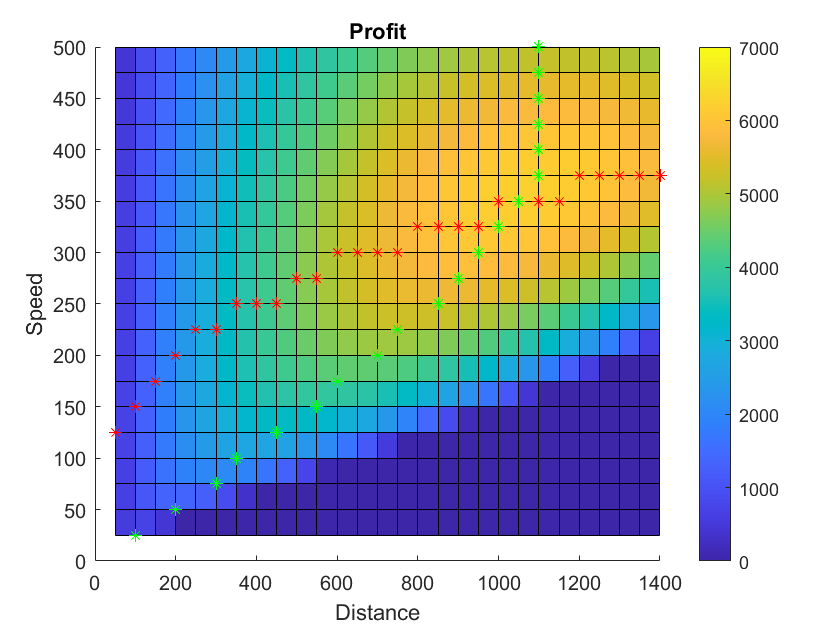

figure(1)
plot(x(icolx),v,'g*')

## Pareto set, Profit and Pollution

WS =     1.0000    0.9999    0.9998    0.9997    0.9996    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9989    0.9988    0.9987    0.9987    0.9986    0.9985    0.9984    0.9983    0.9982    0.9981    0.9980    0.9979    0.9979    0.9978    0.9977    0.9976
    0.9997    0.9994    0.9990    0.9987    0.9983    0.9979    0.9976    0.9972    0.9969    0.9965    0.9962    0.9958    0.9954    0.9951    0.9947    0.9944    0.9940    0.9937    0.9933    0.9929    0.9926    0.9922    0.9919    0.9915    0.9912    0.9908    0.9904    0.9901
    0.9993    0.9985    0.9977    0.9969    0.9961    0.9953    0.9945    0.9937    0.9929    0.9921    0.9912    0.9904    0.9896    0.9888    0.9880    0.9872    0.9864    0.9856    0.9848    0.9840    0.9832    0.9824    0.9816    0.9808    0.9800    0.9792    0.9784    0.9776
    0.9987    0.9972    0.9958    0.9944    0.9929    0.9915    0.9901    0.9887    0.9872    0.9858    0.9844    0.9829    0.9815    0.9801    0.9787  

WS =     0.9996    0.9995    0.9994    0.9993    0.9991    0.9989    0.9987    0.9985    0.9982    0.9979    0.9976    0.9972    0.9968    0.9964    0.9959    0.9955    0.9950    0.9944    0.9939    0.9933    0.9927    0.9921    0.9914    0.9907    0.9900    0.9892    0.9884    0.9876
    0.9993    0.9990    0.9987    0.9983    0.9980    0.9976    0.9972    0.9968    0.9964    0.9959    0.9955    0.9950    0.9945    0.9941    0.9936    0.9930    0.9925    0.9920    0.9914    0.9908    0.9902    0.9896    0.9890    0.9884    0.9877    0.9871    0.9864    0.9857
    0.9989    0.9981    0.9974    0.9966    0.9958    0.9950    0.9942    0.9934    0.9926    0.9917    0.9909    0.9901    0.9892    0.9883    0.9874    0.9866    0.9857    0.9847    0.9838    0.9829    0.9820    0.9810    0.9801    0.9791    0.9781    0.9772    0.9762    0.9752
    0.9983    0.9969    0.9955    0.9941    0.9927    0.9913    0.9899    0.9885    0.9871    0.9857    0.9842    0.9828    0.9813    0.9799    0.9784  

WS =     0.9992    0.9991    0.9990    0.9988    0.9986    0.9983    0.9980    0.9976    0.9971    0.9966    0.9960    0.9954    0.9947    0.9939    0.9931    0.9923    0.9914    0.9904    0.9894    0.9883    0.9872    0.9860    0.9847    0.9834    0.9821    0.9806    0.9792    0.9776
    0.9990    0.9987    0.9983    0.9980    0.9976    0.9972    0.9968    0.9963    0.9959    0.9954    0.9948    0.9942    0.9936    0.9930    0.9924    0.9917    0.9910    0.9902    0.9895    0.9887    0.9879    0.9870    0.9861    0.9852    0.9843    0.9833    0.9823    0.9813
    0.9985    0.9978    0.9971    0.9963    0.9956    0.9948    0.9940    0.9931    0.9923    0.9914    0.9906    0.9897    0.9887    0.9878    0.9869    0.9859    0.9849    0.9839    0.9828    0.9818    0.9807    0.9796    0.9785    0.9774    0.9763    0.9751    0.9739    0.9727
    0.9979    0.9966    0.9953    0.9939    0.9926    0.9912    0.9898    0.9884    0.9870    0.9855    0.9841    0.9826    0.9812    0.9797    0.9782  

WS =     0.9988    0.9987    0.9986    0.9984    0.9981    0.9977    0.9972    0.9966    0.9960    0.9953    0.9944    0.9935    0.9926    0.9915    0.9903    0.9891    0.9878    0.9864    0.9849    0.9833    0.9816    0.9799    0.9781    0.9762    0.9742    0.9721    0.9699    0.9677
    0.9986    0.9983    0.9980    0.9977    0.9973    0.9969    0.9964    0.9959    0.9954    0.9948    0.9941    0.9935    0.9927    0.9920    0.9912    0.9903    0.9895    0.9885    0.9876    0.9865    0.9855    0.9844    0.9833    0.9821    0.9809    0.9796    0.9783    0.9769
    0.9981    0.9975    0.9968    0.9961    0.9953    0.9945    0.9937    0.9929    0.9920    0.9911    0.9902    0.9893    0.9883    0.9873    0.9863    0.9852    0.9841    0.9830    0.9819    0.9807    0.9795    0.9783    0.9770    0.9757    0.9744    0.9731    0.9717    0.9703
    0.9975    0.9963    0.9950    0.9937    0.9924    0.9910    0.9896    0.9883    0.9868    0.9854    0.9840    0.9825    0.9810    0.9795    0.9779  

WS =     0.9984    0.9984    0.9982    0.9979    0.9975    0.9971    0.9964    0.9957    0.9949    0.9940    0.9929    0.9917    0.9904    0.9890    0.9875    0.9859    0.9842    0.9823    0.9804    0.9783    0.9761    0.9738    0.9714    0.9689    0.9663    0.9635    0.9607    0.9577
    0.9982    0.9980    0.9977    0.9973    0.9970    0.9965    0.9960    0.9955    0.9949    0.9942    0.9935    0.9927    0.9918    0.9910    0.9900    0.9890    0.9879    0.9868    0.9856    0.9844    0.9831    0.9818    0.9804    0.9789    0.9774    0.9758    0.9742    0.9725
    0.9977    0.9971    0.9965    0.9958    0.9950    0.9943    0.9935    0.9926    0.9917    0.9908    0.9899    0.9889    0.9878    0.9868    0.9857    0.9845    0.9833    0.9821    0.9809    0.9796    0.9782    0.9769    0.9755    0.9740    0.9725    0.9710    0.9695    0.9679
    0.9972    0.9959    0.9947    0.9934    0.9922    0.9908    0.9895    0.9881    0.9867    0.9853    0.9838    0.9823    0.9808    0.9793    0.9777  

WS =     0.9980    0.9980    0.9978    0.9975    0.9970    0.9964    0.9957    0.9948    0.9938    0.9926    0.9913    0.9899    0.9883    0.9866    0.9847    0.9827    0.9806    0.9783    0.9759    0.9733    0.9706    0.9678    0.9648    0.9616    0.9584    0.9550    0.9514    0.9477
    0.9978    0.9976    0.9973    0.9970    0.9966    0.9962    0.9956    0.9950    0.9944    0.9936    0.9928    0.9919    0.9909    0.9899    0.9888    0.9877    0.9864    0.9851    0.9837    0.9823    0.9808    0.9792    0.9775    0.9758    0.9740    0.9721    0.9702    0.9682
    0.9974    0.9968    0.9962    0.9955    0.9948    0.9940    0.9932    0.9924    0.9915    0.9905    0.9895    0.9885    0.9874    0.9863    0.9851    0.9839    0.9826    0.9813    0.9799    0.9785    0.9770    0.9755    0.9739    0.9723    0.9707    0.9690    0.9672    0.9654
    0.9968    0.9956    0.9944    0.9932    0.9920    0.9907    0.9893    0.9880    0.9866    0.9852    0.9837    0.9822    0.9806    0.9791    0.9775  

WS =     0.9976    0.9976    0.9974    0.9970    0.9965    0.9958    0.9949    0.9939    0.9927    0.9913    0.9898    0.9881    0.9862    0.9841    0.9819    0.9795    0.9770    0.9743    0.9714    0.9683    0.9651    0.9617    0.9581    0.9544    0.9505    0.9464    0.9421    0.9377
    0.9974    0.9972    0.9970    0.9967    0.9963    0.9958    0.9952    0.9946    0.9938    0.9930    0.9921    0.9911    0.9900    0.9889    0.9876    0.9863    0.9849    0.9834    0.9818    0.9802    0.9784    0.9766    0.9746    0.9726    0.9705    0.9684    0.9661    0.9638
    0.9970    0.9965    0.9959    0.9952    0.9945    0.9938    0.9930    0.9921    0.9912    0.9902    0.9892    0.9881    0.9870    0.9857    0.9845    0.9832    0.9818    0.9804    0.9789    0.9774    0.9758    0.9741    0.9724    0.9706    0.9688    0.9669    0.9650    0.9630
    0.9964    0.9953    0.9942    0.9930    0.9918    0.9905    0.9892    0.9878    0.9865    0.9850    0.9835    0.9820    0.9805    0.9789    0.9772  

WS =     0.9972    0.9972    0.9970    0.9966    0.9960    0.9952    0.9942    0.9930    0.9916    0.9900    0.9882    0.9863    0.9841    0.9817    0.9791    0.9764    0.9734    0.9702    0.9669    0.9633    0.9596    0.9556    0.9515    0.9471    0.9426    0.9378    0.9329    0.9278
    0.9970    0.9969    0.9967    0.9964    0.9960    0.9955    0.9948    0.9941    0.9933    0.9924    0.9914    0.9903    0.9891    0.9879    0.9865    0.9850    0.9834    0.9817    0.9799    0.9780    0.9760    0.9740    0.9718    0.9695    0.9671    0.9646    0.9621    0.9594
    0.9966    0.9961    0.9956    0.9950    0.9943    0.9935    0.9927    0.9919    0.9909    0.9899    0.9888    0.9877    0.9865    0.9852    0.9839    0.9825    0.9810    0.9795    0.9779    0.9762    0.9745    0.9727    0.9709    0.9689    0.9669    0.9649    0.9628    0.9606
    0.9960    0.9950    0.9939    0.9928    0.9916    0.9903    0.9890    0.9877    0.9863    0.9849    0.9834    0.9819    0.9803    0.9787    0.9770  

WS =     0.9968    0.9968    0.9966    0.9961    0.9955    0.9946    0.9934    0.9921    0.9905    0.9887    0.9867    0.9844    0.9820    0.9793    0.9763    0.9732    0.9698    0.9662    0.9624    0.9583    0.9540    0.9495    0.9448    0.9399    0.9347    0.9293    0.9236    0.9178
    0.9966    0.9965    0.9963    0.9960    0.9956    0.9951    0.9945    0.9937    0.9928    0.9919    0.9908    0.9896    0.9882    0.9868    0.9853    0.9836    0.9819    0.9800    0.9780    0.9759    0.9737    0.9713    0.9689    0.9663    0.9637    0.9609    0.9580    0.9550
    0.9962    0.9958    0.9953    0.9947    0.9940    0.9933    0.9925    0.9916    0.9906    0.9896    0.9885    0.9873    0.9861    0.9847    0.9833    0.9818    0.9803    0.9786    0.9769    0.9751    0.9733    0.9713    0.9693    0.9672    0.9651    0.9628    0.9605    0.9582
    0.9956    0.9947    0.9936    0.9925    0.9914    0.9902    0.9889    0.9876    0.9862    0.9848    0.9833    0.9817    0.9801    0.9785    0.9767  

WS =     0.9964    0.9964    0.9962    0.9957    0.9949    0.9939    0.9927    0.9912    0.9894    0.9874    0.9851    0.9826    0.9798    0.9768    0.9735    0.9700    0.9662    0.9622    0.9579    0.9533    0.9485    0.9435    0.9382    0.9326    0.9268    0.9207    0.9144    0.9078
    0.9962    0.9962    0.9960    0.9957    0.9953    0.9947    0.9941    0.9933    0.9923    0.9913    0.9901    0.9888    0.9874    0.9858    0.9841    0.9823    0.9803    0.9783    0.9761    0.9738    0.9713    0.9687    0.9660    0.9632    0.9602    0.9572    0.9539    0.9506
    0.9958    0.9954    0.9950    0.9944    0.9938    0.9930    0.9922    0.9913    0.9904    0.9893    0.9882    0.9869    0.9856    0.9842    0.9827    0.9811    0.9795    0.9778    0.9759    0.9740    0.9720    0.9700    0.9678    0.9655    0.9632    0.9608    0.9583    0.9557
    0.9953    0.9943    0.9933    0.9923    0.9912    0.9900    0.9887    0.9874    0.9861    0.9846    0.9831    0.9816    0.9800    0.9783    0.9765  

WS =     0.9960    0.9960    0.9958    0.9952    0.9944    0.9933    0.9919    0.9903    0.9883    0.9861    0.9836    0.9808    0.9777    0.9744    0.9707    0.9668    0.9626    0.9581    0.9534    0.9483    0.9430    0.9374    0.9315    0.9253    0.9189    0.9121    0.9051    0.8978
    0.9958    0.9958    0.9957    0.9954    0.9950    0.9944    0.9937    0.9928    0.9918    0.9907    0.9894    0.9880    0.9865    0.9848    0.9829    0.9809    0.9788    0.9766    0.9742    0.9716    0.9689    0.9661    0.9632    0.9600    0.9568    0.9534    0.9499    0.9462
    0.9954    0.9951    0.9947    0.9941    0.9935    0.9928    0.9920    0.9911    0.9901    0.9890    0.9878    0.9865    0.9852    0.9837    0.9821    0.9805    0.9787    0.9769    0.9749    0.9729    0.9708    0.9686    0.9663    0.9639    0.9614    0.9588    0.9561    0.9533
    0.9949    0.9940    0.9931    0.9921    0.9910    0.9898    0.9886    0.9873    0.9859    0.9845    0.9830    0.9814    0.9798    0.9781    0.9763  

WS =     0.9956    0.9956    0.9954    0.9948    0.9939    0.9927    0.9912    0.9893    0.9872    0.9848    0.9820    0.9790    0.9756    0.9719    0.9679    0.9636    0.9590    0.9541    0.9489    0.9433    0.9375    0.9313    0.9248    0.9181    0.9110    0.9036    0.8959    0.8879
    0.9954    0.9955    0.9953    0.9951    0.9946    0.9940    0.9933    0.9924    0.9913    0.9901    0.9887    0.9872    0.9856    0.9837    0.9817    0.9796    0.9773    0.9749    0.9722    0.9695    0.9666    0.9635    0.9603    0.9569    0.9534    0.9497    0.9458    0.9418
    0.9951    0.9948    0.9944    0.9939    0.9933    0.9926    0.9917    0.9908    0.9898    0.9887    0.9875    0.9861    0.9847    0.9832    0.9815    0.9798    0.9780    0.9760    0.9740    0.9718    0.9695    0.9672    0.9647    0.9622    0.9595    0.9567    0.9538    0.9509
    0.9945    0.9937    0.9928    0.9918    0.9908    0.9897    0.9885    0.9872    0.9858    0.9844    0.9829    0.9813    0.9796    0.9779    0.9760  

WS =     0.9952    0.9952    0.9950    0.9943    0.9934    0.9921    0.9904    0.9884    0.9861    0.9835    0.9805    0.9771    0.9735    0.9695    0.9651    0.9604    0.9554    0.9501    0.9444    0.9383    0.9319    0.9252    0.9182    0.9108    0.9031    0.8950    0.8866    0.8779
    0.9950    0.9951    0.9950    0.9947    0.9943    0.9937    0.9929    0.9919    0.9908    0.9895    0.9881    0.9864    0.9847    0.9827    0.9806    0.9783    0.9758    0.9731    0.9703    0.9674    0.9642    0.9609    0.9574    0.9538    0.9499    0.9459    0.9418    0.9374
    0.9947    0.9944    0.9941    0.9936    0.9930    0.9923    0.9915    0.9906    0.9895    0.9884    0.9871    0.9857    0.9843    0.9827    0.9809    0.9791    0.9772    0.9751    0.9730    0.9707    0.9683    0.9658    0.9632    0.9605    0.9576    0.9547    0.9516    0.9484
    0.9941    0.9934    0.9925    0.9916    0.9906    0.9895    0.9883    0.9870    0.9857    0.9842    0.9827    0.9811    0.9794    0.9777    0.9758  

WS =     0.9948    0.9949    0.9945    0.9939    0.9928    0.9914    0.9897    0.9875    0.9850    0.9821    0.9789    0.9753    0.9713    0.9670    0.9623    0.9572    0.9518    0.9460    0.9399    0.9333    0.9264    0.9192    0.9115    0.9035    0.8952    0.8865    0.8774    0.8679
    0.9947    0.9948    0.9947    0.9944    0.9939    0.9933    0.9925    0.9915    0.9903    0.9889    0.9874    0.9857    0.9838    0.9817    0.9794    0.9769    0.9743    0.9714    0.9684    0.9652    0.9618    0.9583    0.9545    0.9506    0.9465    0.9422    0.9377    0.9331
    0.9943    0.9941    0.9938    0.9933    0.9928    0.9921    0.9912    0.9903    0.9893    0.9881    0.9868    0.9854    0.9838    0.9821    0.9804    0.9784    0.9764    0.9743    0.9720    0.9696    0.9671    0.9644    0.9617    0.9588    0.9558    0.9526    0.9494    0.9460
    0.9938    0.9931    0.9923    0.9914    0.9904    0.9893    0.9882    0.9869    0.9856    0.9841    0.9826    0.9810    0.9793    0.9775    0.9756  

WS =     0.9944    0.9945    0.9941    0.9934    0.9923    0.9908    0.9889    0.9866    0.9839    0.9808    0.9774    0.9735    0.9692    0.9646    0.9595    0.9541    0.9482    0.9420    0.9353    0.9283    0.9209    0.9131    0.9049    0.8963    0.8873    0.8779    0.8681    0.8579
    0.9943    0.9944    0.9943    0.9941    0.9936    0.9930    0.9921    0.9911    0.9898    0.9884    0.9867    0.9849    0.9829    0.9806    0.9782    0.9756    0.9727    0.9697    0.9665    0.9631    0.9595    0.9557    0.9517    0.9475    0.9431    0.9385    0.9337    0.9287
    0.9939    0.9938    0.9935    0.9930    0.9925    0.9918    0.9910    0.9901    0.9890    0.9878    0.9864    0.9850    0.9834    0.9816    0.9798    0.9778    0.9756    0.9734    0.9710    0.9685    0.9658    0.9630    0.9601    0.9571    0.9539    0.9506    0.9471    0.9436
    0.9934    0.9927    0.9920    0.9911    0.9902    0.9891    0.9880    0.9868    0.9854    0.9840    0.9824    0.9808    0.9791    0.9772    0.9753  

WS =     0.9940    0.9941    0.9937    0.9930    0.9918    0.9902    0.9882    0.9857    0.9828    0.9795    0.9758    0.9717    0.9671    0.9621    0.9567    0.9509    0.9446    0.9379    0.9308    0.9233    0.9154    0.9070    0.8982    0.8890    0.8794    0.8693    0.8589    0.8480
    0.9939    0.9940    0.9940    0.9937    0.9933    0.9926    0.9917    0.9906    0.9893    0.9878    0.9861    0.9841    0.9820    0.9796    0.9770    0.9742    0.9712    0.9680    0.9646    0.9610    0.9571    0.9531    0.9488    0.9443    0.9396    0.9347    0.9296    0.9243
    0.9935    0.9934    0.9932    0.9928    0.9922    0.9916    0.9908    0.9898    0.9887    0.9875    0.9861    0.9846    0.9829    0.9811    0.9792    0.9771    0.9749    0.9725    0.9700    0.9674    0.9646    0.9617    0.9586    0.9554    0.9520    0.9485    0.9449    0.9411
    0.9930    0.9924    0.9917    0.9909    0.9900    0.9890    0.9879    0.9866    0.9853    0.9839    0.9823    0.9807    0.9789    0.9770    0.9751  

WS =     0.9936    0.9937    0.9933    0.9925    0.9913    0.9896    0.9874    0.9848    0.9817    0.9782    0.9743    0.9698    0.9650    0.9597    0.9539    0.9477    0.9410    0.9339    0.9263    0.9183    0.9099    0.9009    0.8916    0.8818    0.8715    0.8608    0.8496    0.8380
    0.9935    0.9937    0.9937    0.9934    0.9929    0.9922    0.9913    0.9902    0.9888    0.9872    0.9854    0.9833    0.9811    0.9786    0.9758    0.9729    0.9697    0.9663    0.9627    0.9588    0.9547    0.9504    0.9459    0.9412    0.9362    0.9310    0.9256    0.9199
    0.9931    0.9931    0.9929    0.9925    0.9920    0.9913    0.9905    0.9895    0.9884    0.9872    0.9857    0.9842    0.9825    0.9806    0.9786    0.9764    0.9741    0.9716    0.9690    0.9663    0.9633    0.9603    0.9571    0.9537    0.9502    0.9465    0.9427    0.9387
    0.9926    0.9921    0.9914    0.9907    0.9898    0.9888    0.9877    0.9865    0.9852    0.9837    0.9822    0.9805    0.9787    0.9768    0.9748  

WS =     0.9932    0.9933    0.9929    0.9921    0.9907    0.9889    0.9866    0.9839    0.9806    0.9769    0.9727    0.9680    0.9629    0.9572    0.9511    0.9445    0.9374    0.9299    0.9218    0.9133    0.9043    0.8949    0.8849    0.8745    0.8636    0.8522    0.8403    0.8280
    0.9931    0.9933    0.9933    0.9931    0.9926    0.9919    0.9909    0.9897    0.9883    0.9866    0.9847    0.9825    0.9802    0.9775    0.9746    0.9715    0.9682    0.9646    0.9608    0.9567    0.9524    0.9478    0.9430    0.9380    0.9328    0.9272    0.9215    0.9155
    0.9928    0.9927    0.9926    0.9922    0.9917    0.9911    0.9903    0.9893    0.9881    0.9869    0.9854    0.9838    0.9820    0.9801    0.9780    0.9757    0.9733    0.9708    0.9680    0.9651    0.9621    0.9589    0.9555    0.9520    0.9483    0.9445    0.9404    0.9363
    0.9923    0.9918    0.9912    0.9904    0.9896    0.9886    0.9876    0.9864    0.9850    0.9836    0.9820    0.9804    0.9786    0.9766    0.9746  

WS =     0.9928    0.9929    0.9925    0.9916    0.9902    0.9883    0.9859    0.9830    0.9795    0.9756    0.9711    0.9662    0.9607    0.9548    0.9483    0.9413    0.9338    0.9258    0.9173    0.9083    0.8988    0.8888    0.8783    0.8672    0.8557    0.8436    0.8311    0.8180
    0.9927    0.9930    0.9930    0.9928    0.9923    0.9915    0.9905    0.9893    0.9878    0.9860    0.9840    0.9818    0.9793    0.9765    0.9735    0.9702    0.9667    0.9629    0.9588    0.9546    0.9500    0.9452    0.9402    0.9349    0.9293    0.9235    0.9174    0.9111
    0.9924    0.9924    0.9923    0.9920    0.9915    0.9908    0.9900    0.9890    0.9879    0.9866    0.9851    0.9834    0.9816    0.9796    0.9774    0.9751    0.9726    0.9699    0.9670    0.9640    0.9609    0.9575    0.9540    0.9503    0.9464    0.9424    0.9382    0.9339
    0.9919    0.9914    0.9909    0.9902    0.9894    0.9885    0.9874    0.9862    0.9849    0.9835    0.9819    0.9802    0.9784    0.9764    0.9744  

WS =     0.9924    0.9925    0.9921    0.9912    0.9897    0.9877    0.9851    0.9821    0.9784    0.9743    0.9696    0.9644    0.9586    0.9523    0.9455    0.9381    0.9302    0.9218    0.9128    0.9033    0.8933    0.8827    0.8716    0.8600    0.8478    0.8351    0.8218    0.8080
    0.9923    0.9926    0.9927    0.9924    0.9919    0.9912    0.9901    0.9889    0.9873    0.9855    0.9834    0.9810    0.9784    0.9755    0.9723    0.9688    0.9651    0.9612    0.9569    0.9524    0.9477    0.9426    0.9373    0.9317    0.9259    0.9198    0.9134    0.9067
    0.9920    0.9921    0.9920    0.9917    0.9912    0.9906    0.9898    0.9888    0.9876    0.9862    0.9847    0.9830    0.9811    0.9791    0.9768    0.9744    0.9718    0.9690    0.9661    0.9629    0.9596    0.9561    0.9524    0.9486    0.9446    0.9404    0.9360    0.9314
    0.9915    0.9911    0.9906    0.9900    0.9892    0.9883    0.9873    0.9861    0.9848    0.9833    0.9818    0.9801    0.9782    0.9762    0.9741  

WS =     0.9920    0.9921    0.9917    0.9907    0.9892    0.9871    0.9844    0.9811    0.9773    0.9730    0.9680    0.9625    0.9565    0.9499    0.9427    0.9349    0.9266    0.9178    0.9083    0.8983    0.8878    0.8766    0.8650    0.8527    0.8399    0.8265    0.8126    0.7981
    0.9919    0.9923    0.9923    0.9921    0.9916    0.9908    0.9898    0.9884    0.9868    0.9849    0.9827    0.9802    0.9775    0.9744    0.9711    0.9675    0.9636    0.9595    0.9550    0.9503    0.9453    0.9400    0.9344    0.9286    0.9224    0.9160    0.9093    0.9024
    0.9916    0.9917    0.9917    0.9914    0.9910    0.9903    0.9895    0.9885    0.9873    0.9859    0.9844    0.9826    0.9807    0.9785    0.9762    0.9737    0.9710    0.9681    0.9651    0.9618    0.9584    0.9547    0.9509    0.9469    0.9427    0.9383    0.9338    0.9290
    0.9911    0.9908    0.9903    0.9897    0.9890    0.9881    0.9871    0.9860    0.9847    0.9832    0.9816    0.9799    0.9780    0.9760    0.9739  

WS =     0.9916    0.9917    0.9913    0.9903    0.9886    0.9864    0.9836    0.9802    0.9762    0.9717    0.9665    0.9607    0.9544    0.9474    0.9399    0.9318    0.9230    0.9137    0.9038    0.8933    0.8822    0.8706    0.8583    0.8454    0.8320    0.8180    0.8033    0.7881
    0.9915    0.9919    0.9920    0.9918    0.9913    0.9905    0.9894    0.9880    0.9863    0.9843    0.9820    0.9794    0.9766    0.9734    0.9699    0.9662    0.9621    0.9578    0.9531    0.9482    0.9429    0.9374    0.9316    0.9254    0.9190    0.9123    0.9053    0.8980
    0.9912    0.9914    0.9914    0.9911    0.9907    0.9901    0.9893    0.9883    0.9870    0.9856    0.9840    0.9822    0.9802    0.9780    0.9756    0.9730    0.9703    0.9673    0.9641    0.9607    0.9571    0.9534    0.9494    0.9452    0.9408    0.9363    0.9315    0.9266
    0.9907    0.9905    0.9901    0.9895    0.9888    0.9880    0.9870    0.9858    0.9845    0.9831    0.9815    0.9797    0.9779    0.9758    0.9736  

WS =     0.9912    0.9914    0.9909    0.9898    0.9881    0.9858    0.9829    0.9793    0.9751    0.9703    0.9649    0.9589    0.9522    0.9450    0.9371    0.9286    0.9194    0.9097    0.8993    0.8883    0.8767    0.8645    0.8516    0.8382    0.8241    0.8094    0.7941    0.7781
    0.9911    0.9916    0.9917    0.9914    0.9909    0.9901    0.9890    0.9875    0.9858    0.9837    0.9813    0.9787    0.9757    0.9724    0.9687    0.9648    0.9606    0.9560    0.9512    0.9460    0.9406    0.9348    0.9287    0.9223    0.9156    0.9086    0.9012    0.8936
    0.9908    0.9910    0.9911    0.9909    0.9905    0.9898    0.9890    0.9880    0.9868    0.9853    0.9837    0.9818    0.9798    0.9775    0.9750    0.9724    0.9695    0.9664    0.9631    0.9596    0.9559    0.9520    0.9478    0.9435    0.9390    0.9342    0.9293    0.9241
    0.9904    0.9902    0.9898    0.9893    0.9886    0.9878    0.9868    0.9857    0.9844    0.9829    0.9814    0.9796    0.9777    0.9756    0.9734  

WS =     0.9908    0.9910    0.9905    0.9894    0.9876    0.9852    0.9821    0.9784    0.9740    0.9690    0.9634    0.9571    0.9501    0.9425    0.9343    0.9254    0.9158    0.9057    0.8948    0.8833    0.8712    0.8584    0.8450    0.8309    0.8162    0.8008    0.7848    0.7681
    0.9907    0.9912    0.9913    0.9911    0.9906    0.9898    0.9886    0.9871    0.9853    0.9831    0.9807    0.9779    0.9748    0.9713    0.9676    0.9635    0.9591    0.9543    0.9493    0.9439    0.9382    0.9322    0.9258    0.9191    0.9121    0.9048    0.8972    0.8892
    0.9905    0.9907    0.9908    0.9906    0.9902    0.9896    0.9888    0.9877    0.9865    0.9850    0.9833    0.9814    0.9793    0.9770    0.9745    0.9717    0.9687    0.9655    0.9621    0.9585    0.9546    0.9506    0.9463    0.9418    0.9371    0.9322    0.9271    0.9217
    0.9900    0.9898    0.9895    0.9891    0.9884    0.9876    0.9867    0.9855    0.9843    0.9828    0.9812    0.9794    0.9775    0.9754    0.9732  

WS =     0.9904    0.9906    0.9901    0.9889    0.9871    0.9846    0.9814    0.9775    0.9729    0.9677    0.9618    0.9553    0.9480    0.9401    0.9315    0.9222    0.9122    0.9016    0.8903    0.8783    0.8657    0.8523    0.8383    0.8237    0.8083    0.7923    0.7756    0.7582
    0.9904    0.9908    0.9910    0.9908    0.9903    0.9894    0.9882    0.9866    0.9848    0.9825    0.9800    0.9771    0.9739    0.9703    0.9664    0.9621    0.9575    0.9526    0.9474    0.9418    0.9358    0.9296    0.9229    0.9160    0.9087    0.9011    0.8931    0.8848
    0.9901    0.9904    0.9905    0.9903    0.9899    0.9893    0.9885    0.9875    0.9862    0.9847    0.9830    0.9810    0.9789    0.9765    0.9739    0.9710    0.9679    0.9646    0.9611    0.9574    0.9534    0.9492    0.9448    0.9401    0.9353    0.9302    0.9248    0.9193
    0.9896    0.9895    0.9893    0.9888    0.9882    0.9875    0.9865    0.9854    0.9841    0.9827    0.9811    0.9793    0.9773    0.9752    0.9729  

WS =     0.9900    0.9902    0.9897    0.9885    0.9866    0.9839    0.9806    0.9766    0.9718    0.9664    0.9603    0.9534    0.9459    0.9376    0.9287    0.9190    0.9087    0.8976    0.8858    0.8733    0.8602    0.8463    0.8317    0.8164    0.8004    0.7837    0.7663    0.7482
    0.9900    0.9905    0.9907    0.9905    0.9899    0.9890    0.9878    0.9862    0.9843    0.9820    0.9793    0.9763    0.9730    0.9693    0.9652    0.9608    0.9560    0.9509    0.9454    0.9396    0.9335    0.9269    0.9201    0.9128    0.9053    0.8973    0.8891    0.8804
    0.9897    0.9900    0.9902    0.9900    0.9897    0.9891    0.9883    0.9872    0.9859    0.9844    0.9827    0.9807    0.9784    0.9760    0.9733    0.9703    0.9672    0.9638    0.9601    0.9563    0.9522    0.9478    0.9432    0.9384    0.9334    0.9281    0.9226    0.9168
    0.9892    0.9892    0.9890    0.9886    0.9880    0.9873    0.9864    0.9853    0.9840    0.9826    0.9809    0.9791    0.9772    0.9750    0.9727  

WS =     0.9896    0.9898    0.9893    0.9880    0.9860    0.9833    0.9799    0.9757    0.9708    0.9651    0.9587    0.9516    0.9438    0.9352    0.9259    0.9158    0.9051    0.8935    0.8813    0.8683    0.8546    0.8402    0.8250    0.8091    0.7925    0.7751    0.7570    0.7382
    0.9896    0.9901    0.9903    0.9901    0.9896    0.9887    0.9874    0.9858    0.9838    0.9814    0.9786    0.9755    0.9721    0.9682    0.9640    0.9594    0.9545    0.9492    0.9435    0.9375    0.9311    0.9243    0.9172    0.9097    0.9018    0.8936    0.8850    0.8760
    0.9893    0.9897    0.9899    0.9898    0.9894    0.9889    0.9880    0.9870    0.9857    0.9841    0.9823    0.9803    0.9780    0.9755    0.9727    0.9697    0.9664    0.9629    0.9591    0.9552    0.9509    0.9464    0.9417    0.9367    0.9315    0.9261    0.9204    0.9144
    0.9889    0.9889    0.9887    0.9884    0.9878    0.9871    0.9862    0.9851    0.9839    0.9824    0.9808    0.9790    0.9770    0.9748    0.9725  

WS =     0.9892    0.9894    0.9889    0.9876    0.9855    0.9827    0.9791    0.9748    0.9697    0.9638    0.9572    0.9498    0.9416    0.9327    0.9231    0.9126    0.9015    0.8895    0.8768    0.8633    0.8491    0.8341    0.8184    0.8019    0.7846    0.7666    0.7478    0.7282
    0.9892    0.9898    0.9900    0.9898    0.9893    0.9883    0.9870    0.9853    0.9832    0.9808    0.9780    0.9748    0.9712    0.9672    0.9628    0.9581    0.9530    0.9475    0.9416    0.9354    0.9287    0.9217    0.9143    0.9065    0.8984    0.8899    0.8809    0.8717
    0.9889    0.9894    0.9896    0.9895    0.9892    0.9886    0.9878    0.9867    0.9854    0.9838    0.9820    0.9799    0.9775    0.9749    0.9721    0.9690    0.9656    0.9620    0.9582    0.9540    0.9497    0.9450    0.9402    0.9350    0.9297    0.9240    0.9181    0.9120
    0.9885    0.9886    0.9884    0.9881    0.9876    0.9869    0.9861    0.9850    0.9837    0.9823    0.9807    0.9788    0.9768    0.9746    0.9722  

WS =     0.9888    0.9890    0.9885    0.9871    0.9850    0.9821    0.9783    0.9738    0.9686    0.9625    0.9556    0.9480    0.9395    0.9303    0.9203    0.9095    0.8979    0.8855    0.8723    0.8583    0.8436    0.8281    0.8117    0.7946    0.7767    0.7580    0.7385    0.7183
    0.9888    0.9894    0.9896    0.9895    0.9889    0.9880    0.9866    0.9849    0.9827    0.9802    0.9773    0.9740    0.9703    0.9662    0.9617    0.9568    0.9515    0.9458    0.9397    0.9332    0.9264    0.9191    0.9115    0.9034    0.8950    0.8861    0.8769    0.8673
    0.9885    0.9890    0.9893    0.9892    0.9889    0.9884    0.9875    0.9865    0.9851    0.9835    0.9816    0.9795    0.9771    0.9744    0.9715    0.9683    0.9649    0.9611    0.9572    0.9529    0.9484    0.9437    0.9386    0.9333    0.9278    0.9220    0.9159    0.9096
    0.9881    0.9882    0.9882    0.9879    0.9874    0.9868    0.9859    0.9849    0.9836    0.9822    0.9805    0.9787    0.9766    0.9744    0.9720  

WS =     0.9884    0.9886    0.9881    0.9867    0.9845    0.9814    0.9776    0.9729    0.9675    0.9612    0.9541    0.9461    0.9374    0.9278    0.9175    0.9063    0.8943    0.8814    0.8678    0.8533    0.8381    0.8220    0.8051    0.7873    0.7688    0.7495    0.7293    0.7083
    0.9884    0.9891    0.9893    0.9892    0.9886    0.9876    0.9862    0.9844    0.9822    0.9796    0.9766    0.9732    0.9694    0.9651    0.9605    0.9554    0.9499    0.9441    0.9378    0.9311    0.9240    0.9165    0.9086    0.9003    0.8915    0.8824    0.8728    0.8629
    0.9881    0.9887    0.9889    0.9889    0.9887    0.9881    0.9873    0.9862    0.9848    0.9832    0.9813    0.9791    0.9766    0.9739    0.9709    0.9676    0.9641    0.9603    0.9562    0.9518    0.9472    0.9423    0.9371    0.9317    0.9259    0.9199    0.9137    0.9071
    0.9877    0.9879    0.9879    0.9877    0.9872    0.9866    0.9858    0.9847    0.9835    0.9820    0.9804    0.9785    0.9765    0.9742    0.9717  

WS =     0.9880    0.9882    0.9877    0.9862    0.9839    0.9808    0.9768    0.9720    0.9664    0.9599    0.9525    0.9443    0.9353    0.9254    0.9147    0.9031    0.8907    0.8774    0.8633    0.8483    0.8325    0.8159    0.7984    0.7801    0.7609    0.7409    0.7200    0.6983
    0.9880    0.9887    0.9890    0.9888    0.9883    0.9873    0.9858    0.9840    0.9817    0.9791    0.9759    0.9724    0.9685    0.9641    0.9593    0.9541    0.9484    0.9424    0.9359    0.9290    0.9216    0.9139    0.9057    0.8971    0.8881    0.8786    0.8688    0.8585
    0.9878    0.9883    0.9886    0.9887    0.9884    0.9879    0.9870    0.9859    0.9846    0.9829    0.9809    0.9787    0.9762    0.9734    0.9703    0.9670    0.9633    0.9594    0.9552    0.9507    0.9459    0.9409    0.9356    0.9300    0.9241    0.9179    0.9114    0.9047
    0.9873    0.9876    0.9876    0.9874    0.9870    0.9864    0.9856    0.9846    0.9834    0.9819    0.9803    0.9784    0.9763    0.9740    0.9715  

WS =     0.9876    0.9879    0.9872    0.9858    0.9834    0.9802    0.9761    0.9711    0.9653    0.9585    0.9510    0.9425    0.9332    0.9229    0.9119    0.8999    0.8871    0.8734    0.8588    0.8433    0.8270    0.8098    0.7918    0.7728    0.7530    0.7323    0.7108    0.6883
    0.9876    0.9884    0.9886    0.9885    0.9879    0.9869    0.9854    0.9836    0.9812    0.9785    0.9753    0.9716    0.9676    0.9631    0.9581    0.9527    0.9469    0.9407    0.9340    0.9268    0.9193    0.9113    0.9028    0.8940    0.8847    0.8749    0.8647    0.8541
    0.9874    0.9880    0.9883    0.9884    0.9882    0.9876    0.9868    0.9857    0.9843    0.9826    0.9806    0.9783    0.9757    0.9729    0.9697    0.9663    0.9625    0.9585    0.9542    0.9496    0.9447    0.9395    0.9340    0.9283    0.9222    0.9158    0.9092    0.9023
    0.9870    0.9873    0.9873    0.9872    0.9868    0.9863    0.9855    0.9845    0.9832    0.9818    0.9801    0.9782    0.9761    0.9738    0.9713  

WS =     0.9872    0.9875    0.9868    0.9853    0.9829    0.9796    0.9753    0.9702    0.9642    0.9572    0.9494    0.9407    0.9310    0.9205    0.9091    0.8967    0.8835    0.8693    0.8543    0.8383    0.8215    0.8038    0.7851    0.7656    0.7451    0.7238    0.7015    0.6784
    0.9872    0.9880    0.9883    0.9882    0.9876    0.9865    0.9851    0.9831    0.9807    0.9779    0.9746    0.9709    0.9667    0.9620    0.9569    0.9514    0.9454    0.9389    0.9320    0.9247    0.9169    0.9087    0.9000    0.8908    0.8812    0.8712    0.8607    0.8497
    0.9870    0.9877    0.9880    0.9881    0.9879    0.9874    0.9865    0.9854    0.9840    0.9823    0.9802    0.9779    0.9753    0.9724    0.9691    0.9656    0.9618    0.9576    0.9532    0.9485    0.9435    0.9381    0.9325    0.9266    0.9203    0.9138    0.9070    0.8998
    0.9866    0.9869    0.9871    0.9870    0.9867    0.9861    0.9853    0.9843    0.9831    0.9817    0.9800    0.9781    0.9759    0.9736    0.9710  

WS =     0.9868    0.9871    0.9864    0.9849    0.9824    0.9789    0.9746    0.9693    0.9631    0.9559    0.9478    0.9388    0.9289    0.9180    0.9063    0.8935    0.8799    0.8653    0.8498    0.8333    0.8160    0.7977    0.7785    0.7583    0.7372    0.7152    0.6923    0.6684
    0.9868    0.9876    0.9880    0.9878    0.9872    0.9862    0.9847    0.9827    0.9802    0.9773    0.9739    0.9701    0.9658    0.9610    0.9557    0.9500    0.9439    0.9372    0.9301    0.9226    0.9145    0.9060    0.8971    0.8877    0.8778    0.8674    0.8566    0.8453
    0.9866    0.9873    0.9877    0.9878    0.9876    0.9871    0.9863    0.9852    0.9837    0.9820    0.9799    0.9775    0.9748    0.9718    0.9685    0.9649    0.9610    0.9568    0.9522    0.9474    0.9422    0.9367    0.9310    0.9249    0.9185    0.9118    0.9047    0.8974
    0.9862    0.9866    0.9868    0.9867    0.9865    0.9859    0.9852    0.9842    0.9830    0.9815    0.9798    0.9779    0.9758    0.9734    0.9708  

WS =     0.9864    0.9867    0.9860    0.9844    0.9818    0.9783    0.9738    0.9684    0.9620    0.9546    0.9463    0.9370    0.9268    0.9156    0.9034    0.8903    0.8763    0.8613    0.8453    0.8283    0.8105    0.7916    0.7718    0.7510    0.7293    0.7066    0.6830    0.6584
    0.9864    0.9873    0.9876    0.9875    0.9869    0.9858    0.9843    0.9822    0.9797    0.9767    0.9732    0.9693    0.9649    0.9600    0.9546    0.9487    0.9423    0.9355    0.9282    0.9204    0.9122    0.9034    0.8942    0.8845    0.8743    0.8637    0.8526    0.8409
    0.9862    0.9870    0.9874    0.9876    0.9874    0.9869    0.9861    0.9849    0.9834    0.9817    0.9796    0.9771    0.9744    0.9713    0.9680    0.9643    0.9602    0.9559    0.9512    0.9463    0.9410    0.9354    0.9294    0.9232    0.9166    0.9097    0.9025    0.8950
    0.9858    0.9863    0.9865    0.9865    0.9863    0.9858    0.9850    0.9841    0.9828    0.9814    0.9797    0.9778    0.9756    0.9732    0.9705  

WS =     0.9860    0.9863    0.9856    0.9840    0.9813    0.9777    0.9731    0.9675    0.9609    0.9533    0.9447    0.9352    0.9247    0.9131    0.9006    0.8872    0.8727    0.8572    0.8408    0.8234    0.8049    0.7855    0.7651    0.7438    0.7214    0.6981    0.6737    0.6484
    0.9861    0.9869    0.9873    0.9872    0.9866    0.9855    0.9839    0.9818    0.9792    0.9761    0.9726    0.9685    0.9640    0.9589    0.9534    0.9474    0.9408    0.9338    0.9263    0.9183    0.9098    0.9008    0.8913    0.8814    0.8709    0.8600    0.8485    0.8366
    0.9858    0.9867    0.9871    0.9873    0.9871    0.9866    0.9858    0.9847    0.9832    0.9814    0.9792    0.9767    0.9739    0.9708    0.9674    0.9636    0.9595    0.9550    0.9503    0.9452    0.9397    0.9340    0.9279    0.9215    0.9147    0.9077    0.9003    0.8926
    0.9855    0.9860    0.9863    0.9863    0.9861    0.9856    0.9849    0.9839    0.9827    0.9813    0.9796    0.9776    0.9754    0.9730    0.9703  

WS =     0.9856    0.9859    0.9852    0.9835    0.9808    0.9771    0.9723    0.9666    0.9598    0.9520    0.9432    0.9334    0.9225    0.9107    0.8978    0.8840    0.8691    0.8532    0.8363    0.8184    0.7994    0.7795    0.7585    0.7365    0.7135    0.6895    0.6645    0.6385
    0.9857    0.9866    0.9870    0.9869    0.9862    0.9851    0.9835    0.9814    0.9787    0.9756    0.9719    0.9677    0.9631    0.9579    0.9522    0.9460    0.9393    0.9321    0.9244    0.9162    0.9074    0.8982    0.8885    0.8782    0.8675    0.8562    0.8444    0.8322
    0.9855    0.9863    0.9868    0.9870    0.9869    0.9864    0.9856    0.9844    0.9829    0.9810    0.9789    0.9764    0.9735    0.9703    0.9668    0.9629    0.9587    0.9542    0.9493    0.9440    0.9385    0.9326    0.9264    0.9198    0.9129    0.9056    0.8980    0.8901
    0.9851    0.9857    0.9860    0.9860    0.9859    0.9854    0.9847    0.9838    0.9826    0.9811    0.9794    0.9775    0.9753    0.9728    0.9701  

WS =     0.9852    0.9855    0.9848    0.9831    0.9803    0.9764    0.9716    0.9656    0.9587    0.9507    0.9416    0.9315    0.9204    0.9083    0.8950    0.8808    0.8655    0.8492    0.8318    0.8134    0.7939    0.7734    0.7518    0.7293    0.7056    0.6810    0.6552    0.6285
    0.9853    0.9862    0.9866    0.9865    0.9859    0.9848    0.9831    0.9809    0.9782    0.9750    0.9712    0.9670    0.9622    0.9569    0.9510    0.9447    0.9378    0.9304    0.9225    0.9140    0.9051    0.8956    0.8856    0.8751    0.8640    0.8525    0.8404    0.8278
    0.9851    0.9860    0.9865    0.9868    0.9866    0.9861    0.9853    0.9841    0.9826    0.9807    0.9785    0.9760    0.9730    0.9698    0.9662    0.9622    0.9579    0.9533    0.9483    0.9429    0.9372    0.9312    0.9248    0.9181    0.9110    0.9036    0.8958    0.8877
    0.9847    0.9853    0.9857    0.9858    0.9857    0.9853    0.9846    0.9836    0.9825    0.9810    0.9793    0.9773    0.9751    0.9726    0.9698  

WS =     0.9848    0.9851    0.9844    0.9826    0.9797    0.9758    0.9708    0.9647    0.9576    0.9494    0.9401    0.9297    0.9183    0.9058    0.8922    0.8776    0.8619    0.8451    0.8273    0.8084    0.7884    0.7673    0.7452    0.7220    0.6977    0.6724    0.6460    0.6185
    0.9849    0.9859    0.9863    0.9862    0.9856    0.9844    0.9827    0.9805    0.9777    0.9744    0.9706    0.9662    0.9613    0.9558    0.9498    0.9433    0.9363    0.9287    0.9206    0.9119    0.9027    0.8930    0.8827    0.8719    0.8606    0.8487    0.8363    0.8234
    0.9847    0.9856    0.9862    0.9865    0.9864    0.9859    0.9851    0.9839    0.9823    0.9804    0.9782    0.9756    0.9726    0.9693    0.9656    0.9616    0.9572    0.9524    0.9473    0.9418    0.9360    0.9298    0.9233    0.9164    0.9091    0.9015    0.8936    0.8853
    0.9843    0.9850    0.9854    0.9856    0.9855    0.9851    0.9844    0.9835    0.9823    0.9809    0.9792    0.9772    0.9749    0.9724    0.9696  

WS =     0.9844    0.9847    0.9840    0.9822    0.9792    0.9752    0.9701    0.9638    0.9565    0.9481    0.9385    0.9279    0.9162    0.9034    0.8894    0.8744    0.8583    0.8411    0.8228    0.8034    0.7828    0.7612    0.7385    0.7147    0.6898    0.6638    0.6367    0.6085
    0.9845    0.9855    0.9860    0.9859    0.9852    0.9841    0.9823    0.9800    0.9772    0.9738    0.9699    0.9654    0.9604    0.9548    0.9487    0.9420    0.9348    0.9270    0.9186    0.9098    0.9004    0.8904    0.8799    0.8688    0.8572    0.8450    0.8323    0.8190
    0.9843    0.9853    0.9859    0.9862    0.9861    0.9856    0.9848    0.9836    0.9821    0.9801    0.9778    0.9752    0.9722    0.9688    0.9650    0.9609    0.9564    0.9515    0.9463    0.9407    0.9348    0.9284    0.9218    0.9147    0.9073    0.8995    0.8913    0.8828
    0.9840    0.9847    0.9852    0.9854    0.9853    0.9849    0.9843    0.9834    0.9822    0.9807    0.9790    0.9770    0.9747    0.9722    0.9694  

WS =     0.9840    0.9844    0.9836    0.9817    0.9787    0.9746    0.9693    0.9629    0.9554    0.9467    0.9370    0.9261    0.9141    0.9009    0.8866    0.8712    0.8547    0.8370    0.8183    0.7984    0.7773    0.7552    0.7319    0.7075    0.6819    0.6553    0.6275    0.5986
    0.9841    0.9852    0.9856    0.9855    0.9849    0.9837    0.9819    0.9796    0.9767    0.9732    0.9692    0.9646    0.9595    0.9538    0.9475    0.9406    0.9332    0.9253    0.9167    0.9076    0.8980    0.8878    0.8770    0.8656    0.8537    0.8413    0.8282    0.8146
    0.9839    0.9850    0.9856    0.9859    0.9859    0.9854    0.9846    0.9834    0.9818    0.9798    0.9775    0.9748    0.9717    0.9682    0.9644    0.9602    0.9556    0.9507    0.9453    0.9396    0.9335    0.9271    0.9202    0.9130    0.9054    0.8975    0.8891    0.8804
    0.9836    0.9844    0.9849    0.9851    0.9851    0.9847    0.9841    0.9832    0.9821    0.9806    0.9789    0.9769    0.9746    0.9720    0.9691  

WS =     0.9836    0.9840    0.9832    0.9813    0.9782    0.9739    0.9685    0.9620    0.9543    0.9454    0.9354    0.9243    0.9119    0.8985    0.8838    0.8680    0.8511    0.8330    0.8138    0.7934    0.7718    0.7491    0.7252    0.7002    0.6740    0.6467    0.6182    0.5886
    0.9837    0.9848    0.9853    0.9852    0.9846    0.9833    0.9815    0.9791    0.9762    0.9726    0.9685    0.9638    0.9586    0.9527    0.9463    0.9393    0.9317    0.9236    0.9148    0.9055    0.8956    0.8852    0.8741    0.8625    0.8503    0.8375    0.8242    0.8102
    0.9835    0.9846    0.9853    0.9857    0.9856    0.9852    0.9843    0.9831    0.9815    0.9795    0.9771    0.9744    0.9713    0.9677    0.9638    0.9595    0.9548    0.9498    0.9443    0.9385    0.9323    0.9257    0.9187    0.9113    0.9036    0.8954    0.8869    0.8780
    0.9832    0.9841    0.9846    0.9849    0.9849    0.9846    0.9840    0.9831    0.9819    0.9805    0.9787    0.9767    0.9744    0.9718    0.9689  

WS =     0.9832    0.9836    0.9828    0.9808    0.9777    0.9733    0.9678    0.9611    0.9532    0.9441    0.9339    0.9224    0.9098    0.8960    0.8810    0.8649    0.8475    0.8290    0.8093    0.7884    0.7663    0.7430    0.7186    0.6929    0.6661    0.6381    0.6090    0.5786
    0.9833    0.9844    0.9850    0.9849    0.9842    0.9830    0.9811    0.9787    0.9757    0.9721    0.9679    0.9631    0.9577    0.9517    0.9451    0.9379    0.9302    0.9218    0.9129    0.9034    0.8933    0.8825    0.8712    0.8593    0.8469    0.8338    0.8201    0.8059
    0.9832    0.9843    0.9850    0.9854    0.9853    0.9849    0.9841    0.9828    0.9812    0.9792    0.9768    0.9740    0.9708    0.9672    0.9632    0.9588    0.9541    0.9489    0.9433    0.9374    0.9310    0.9243    0.9172    0.9096    0.9017    0.8934    0.8847    0.8755
    0.9828    0.9837    0.9843    0.9847    0.9847    0.9844    0.9838    0.9830    0.9818    0.9804    0.9786    0.9766    0.9742    0.9716    0.9686  

WS =     0.9828    0.9832    0.9824    0.9804    0.9771    0.9727    0.9670    0.9602    0.9521    0.9428    0.9323    0.9206    0.9077    0.8936    0.8782    0.8617    0.8439    0.8249    0.8048    0.7834    0.7608    0.7369    0.7119    0.6857    0.6582    0.6296    0.5997    0.5686
    0.9829    0.9841    0.9846    0.9846    0.9839    0.9826    0.9807    0.9783    0.9752    0.9715    0.9672    0.9623    0.9568    0.9507    0.9439    0.9366    0.9287    0.9201    0.9110    0.9012    0.8909    0.8799    0.8684    0.8562    0.8434    0.8300    0.8161    0.8015
    0.9828    0.9840    0.9847    0.9851    0.9851    0.9847    0.9838    0.9826    0.9810    0.9789    0.9765    0.9736    0.9704    0.9667    0.9626    0.9582    0.9533    0.9480    0.9424    0.9363    0.9298    0.9229    0.9156    0.9079    0.8998    0.8913    0.8824    0.8731
    0.9824    0.9834    0.9841    0.9844    0.9845    0.9842    0.9837    0.9828    0.9817    0.9802    0.9785    0.9764    0.9740    0.9714    0.9684  

WS = 10×28
    0.9824    0.9828    0.9820    0.9799    0.9766    0.9721    0.9663    0.9593    0.9510    0.9415    0.9308    0.9188    0.9056    0.8911    0.8754    0.8585    0.8403    0.8209    0.8003    0.7784    0.7552    0.7309    0.7053    0.6784    0.6503    0.6210    0.5905    0.5586
    0.9825    0.9837    0.9843    0.9842    0.9836    0.9823    0.9804    0.9778    0.9747    0.9709    0.9665    0.9615    0.9559    0.9496    0.9427    0.9353    0.9272    0.9184    0.9091    0.8991    0.8885    0.8773    0.8655    0.8531    0.8400    0.8263    0.8120    0.7971
    0.9824    0.9836    0.9844    0.9848    0.9848    0.9844    0.9836    0.9823    0.9807    0.9786    0.9761    0.9732    0.9699    0.9662    0.9620    0.9575    0.9525    0.9472    0.9414    0.9352    0.9286    0.9215    0.9141    0.9062    0.8980    0.8893    0.8802    0.8707
    0.9821    0.9831    0.9838    0.9842    0.9843    0.9841    0.9835    0.9827    0.9816    0.9801    0.9783    0.9762    0.9739    0.9712    0.

WS = 10×28
    0.9820    0.9824    0.9816    0.9795    0.9761    0.9714    0.9655    0.9583    0.9499    0.9402    0.9292    0.9170    0.9034    0.8887    0.8726    0.8553    0.8367    0.8169    0.7957    0.7734    0.7497    0.7248    0.6986    0.6712    0.6424    0.6124    0.5812    0.5487
    0.9822    0.9834    0.9840    0.9839    0.9832    0.9819    0.9800    0.9774    0.9742    0.9703    0.9658    0.9607    0.9550    0.9486    0.9416    0.9339    0.9256    0.9167    0.9072    0.8970    0.8862    0.8747    0.8626    0.8499    0.8366    0.8226    0.8079    0.7927
    0.9820    0.9833    0.9841    0.9846    0.9846    0.9842    0.9833    0.9821    0.9804    0.9783    0.9758    0.9728    0.9695    0.9657    0.9615    0.9568    0.9518    0.9463    0.9404    0.9341    0.9273    0.9201    0.9125    0.9045    0.8961    0.8872    0.8780    0.8683
    0.9817    0.9828    0.9835    0.9840    0.9841    0.9839    0.9834    0.9826    0.9814    0.9800    0.9782    0.9761    0.9737    0.9710    0.

WS = 10×28
    0.9816    0.9820    0.9812    0.9790    0.9756    0.9708    0.9648    0.9574    0.9488    0.9389    0.9277    0.9151    0.9013    0.8862    0.8698    0.8521    0.8331    0.8128    0.7912    0.7684    0.7442    0.7187    0.6920    0.6639    0.6345    0.6039    0.5719    0.5387
    0.9818    0.9830    0.9836    0.9836    0.9829    0.9816    0.9796    0.9769    0.9737    0.9697    0.9652    0.9599    0.9541    0.9476    0.9404    0.9326    0.9241    0.9150    0.9052    0.8948    0.8838    0.8721    0.8598    0.8468    0.8331    0.8188    0.8039    0.7883
    0.9816    0.9829    0.9838    0.9843    0.9843    0.9839    0.9831    0.9818    0.9801    0.9780    0.9754    0.9724    0.9690    0.9652    0.9609    0.9561    0.9510    0.9454    0.9394    0.9329    0.9261    0.9188    0.9110    0.9028    0.8942    0.8852    0.8757    0.8658
    0.9813    0.9824    0.9833    0.9837    0.9839    0.9837    0.9832    0.9824    0.9813    0.9798    0.9781    0.9759    0.9735    0.9708    0.

WS = 10×28
    0.9812    0.9816    0.9808    0.9786    0.9750    0.9702    0.9640    0.9565    0.9477    0.9376    0.9261    0.9133    0.8992    0.8838    0.8670    0.8489    0.8295    0.8088    0.7867    0.7634    0.7387    0.7126    0.6853    0.6566    0.6266    0.5953    0.5627    0.5287
    0.9814    0.9827    0.9833    0.9833    0.9826    0.9812    0.9792    0.9765    0.9732    0.9692    0.9645    0.9592    0.9532    0.9465    0.9392    0.9312    0.9226    0.9133    0.9033    0.8927    0.8814    0.8695    0.8569    0.8436    0.8297    0.8151    0.7998    0.7839
    0.9812    0.9826    0.9835    0.9840    0.9841    0.9837    0.9828    0.9816    0.9798    0.9777    0.9751    0.9720    0.9686    0.9646    0.9603    0.9555    0.9502    0.9445    0.9384    0.9318    0.9248    0.9174    0.9095    0.9011    0.8924    0.8832    0.8735    0.8634
    0.9809    0.9821    0.9830    0.9835    0.9837    0.9836    0.9831    0.9823    0.9812    0.9797    0.9779    0.9758    0.9733    0.9706    0.

WS = 10×28
    0.9808    0.9812    0.9804    0.9781    0.9745    0.9696    0.9633    0.9556    0.9466    0.9363    0.9245    0.9115    0.8971    0.8813    0.8642    0.8457    0.8259    0.8048    0.7822    0.7584    0.7331    0.7066    0.6786    0.6494    0.6187    0.5868    0.5534    0.5187
    0.9810    0.9823    0.9830    0.9829    0.9822    0.9808    0.9788    0.9761    0.9727    0.9686    0.9638    0.9584    0.9523    0.9455    0.9380    0.9299    0.9211    0.9116    0.9014    0.8906    0.8791    0.8669    0.8540    0.8405    0.8262    0.8114    0.7958    0.7795
    0.9808    0.9823    0.9832    0.9837    0.9838    0.9834    0.9826    0.9813    0.9796    0.9774    0.9747    0.9717    0.9681    0.9641    0.9597    0.9548    0.9495    0.9437    0.9374    0.9307    0.9236    0.9160    0.9079    0.8995    0.8905    0.8811    0.8713    0.8610
    0.9806    0.9818    0.9827    0.9833    0.9835    0.9834    0.9829    0.9822    0.9810    0.9796    0.9778    0.9756    0.9732    0.9704    0.

WS = 10×28
    0.9804    0.9809    0.9799    0.9777    0.9740    0.9689    0.9625    0.9547    0.9455    0.9349    0.9230    0.9097    0.8950    0.8789    0.8614    0.8426    0.8223    0.8007    0.7777    0.7534    0.7276    0.7005    0.6720    0.6421    0.6108    0.5782    0.5442    0.5088
    0.9806    0.9819    0.9826    0.9826    0.9819    0.9805    0.9784    0.9756    0.9721    0.9680    0.9631    0.9576    0.9514    0.9445    0.9368    0.9285    0.9196    0.9099    0.8995    0.8884    0.8767    0.8643    0.8511    0.8373    0.8228    0.8076    0.7917    0.7751
    0.9805    0.9819    0.9829    0.9835    0.9836    0.9832    0.9823    0.9810    0.9793    0.9771    0.9744    0.9713    0.9677    0.9636    0.9591    0.9541    0.9487    0.9428    0.9364    0.9296    0.9223    0.9146    0.9064    0.8978    0.8886    0.8791    0.8690    0.8585
    0.9802    0.9815    0.9824    0.9830    0.9833    0.9832    0.9828    0.9820    0.9809    0.9794    0.9776    0.9755    0.9730    0.9702    0.

WS = 10×28
    0.9800    0.9805    0.9795    0.9772    0.9735    0.9683    0.9618    0.9538    0.9444    0.9336    0.9214    0.9078    0.8928    0.8764    0.8586    0.8394    0.8187    0.7967    0.7732    0.7484    0.7221    0.6944    0.6653    0.6348    0.6029    0.5696    0.5349    0.4988
    0.9802    0.9816    0.9823    0.9823    0.9816    0.9801    0.9780    0.9752    0.9716    0.9674    0.9625    0.9568    0.9505    0.9434    0.9357    0.9272    0.9180    0.9082    0.8976    0.8863    0.8743    0.8617    0.8483    0.8342    0.8194    0.8039    0.7877    0.7708
    0.9801    0.9816    0.9826    0.9832    0.9833    0.9829    0.9821    0.9808    0.9790    0.9768    0.9741    0.9709    0.9672    0.9631    0.9585    0.9534    0.9479    0.9419    0.9354    0.9285    0.9211    0.9132    0.9049    0.8961    0.8868    0.8770    0.8668    0.8561
    0.9798    0.9812    0.9822    0.9828    0.9831    0.9831    0.9826    0.9819    0.9808    0.9793    0.9775    0.9753    0.9728    0.9699    0.

WS = 10×28
    0.9796    0.9801    0.9791    0.9768    0.9729    0.9677    0.9610    0.9529    0.9433    0.9323    0.9199    0.9060    0.8907    0.8740    0.8558    0.8362    0.8151    0.7926    0.7687    0.7434    0.7166    0.6884    0.6587    0.6276    0.5950    0.5611    0.5257    0.4888
    0.9798    0.9812    0.9819    0.9819    0.9812    0.9798    0.9776    0.9747    0.9711    0.9668    0.9618    0.9560    0.9496    0.9424    0.9345    0.9259    0.9165    0.9065    0.8957    0.8842    0.8720    0.8590    0.8454    0.8310    0.8159    0.8001    0.7836    0.7664
    0.9797    0.9813    0.9823    0.9829    0.9830    0.9827    0.9818    0.9805    0.9787    0.9765    0.9737    0.9705    0.9668    0.9626    0.9579    0.9528    0.9471    0.9410    0.9345    0.9274    0.9199    0.9118    0.9033    0.8944    0.8849    0.8750    0.8646    0.8537
    0.9794    0.9808    0.9819    0.9826    0.9829    0.9829    0.9825    0.9818    0.9807    0.9792    0.9774    0.9752    0.9726    0.9697    0.

WS = 10×28
    0.9792    0.9797    0.9787    0.9763    0.9724    0.9671    0.9602    0.9520    0.9422    0.9310    0.9183    0.9042    0.8886    0.8715    0.8530    0.8330    0.8115    0.7886    0.7642    0.7384    0.7111    0.6823    0.6520    0.6203    0.5871    0.5525    0.5164    0.4788
    0.9794    0.9809    0.9816    0.9816    0.9809    0.9794    0.9772    0.9743    0.9706    0.9662    0.9611    0.9553    0.9487    0.9414    0.9333    0.9245    0.9150    0.9047    0.8938    0.8821    0.8696    0.8564    0.8425    0.8279    0.8125    0.7964    0.7796    0.7620
    0.9793    0.9809    0.9820    0.9827    0.9828    0.9824    0.9816    0.9803    0.9785    0.9762    0.9734    0.9701    0.9663    0.9621    0.9573    0.9521    0.9464    0.9402    0.9335    0.9263    0.9186    0.9105    0.9018    0.8927    0.8830    0.8729    0.8623    0.8512
    0.9791    0.9805    0.9816    0.9823    0.9827    0.9827    0.9824    0.9816    0.9805    0.9791    0.9772    0.9750    0.9725    0.9695    0.

WS = 10×28
    0.9788    0.9793    0.9783    0.9759    0.9719    0.9664    0.9595    0.9511    0.9411    0.9297    0.9168    0.9024    0.8865    0.8691    0.8502    0.8298    0.8079    0.7846    0.7597    0.7334    0.7055    0.6762    0.6454    0.6131    0.5793    0.5439    0.5072    0.4689
    0.9790    0.9805    0.9813    0.9813    0.9805    0.9791    0.9768    0.9739    0.9701    0.9657    0.9604    0.9545    0.9478    0.9403    0.9321    0.9232    0.9135    0.9030    0.8919    0.8799    0.8672    0.8538    0.8396    0.8247    0.8091    0.7927    0.7755    0.7576
    0.9789    0.9806    0.9817    0.9824    0.9825    0.9822    0.9814    0.9800    0.9782    0.9759    0.9730    0.9697    0.9659    0.9616    0.9567    0.9514    0.9456    0.9393    0.9325    0.9252    0.9174    0.9091    0.9003    0.8910    0.8812    0.8709    0.8601    0.8488
    0.9787    0.9802    0.9813    0.9821    0.9825    0.9825    0.9822    0.9815    0.9804    0.9789    0.9771    0.9749    0.9723    0.9693    0.

WS = 10×28
    0.9784    0.9789    0.9779    0.9754    0.9714    0.9658    0.9587    0.9501    0.9400    0.9284    0.9152    0.9005    0.8843    0.8666    0.8474    0.8266    0.8043    0.7805    0.7552    0.7284    0.7000    0.6701    0.6387    0.6058    0.5714    0.5354    0.4979    0.4589
    0.9786    0.9802    0.9809    0.9810    0.9802    0.9787    0.9764    0.9734    0.9696    0.9651    0.9598    0.9537    0.9469    0.9393    0.9309    0.9218    0.9120    0.9013    0.8899    0.8778    0.8649    0.8512    0.8368    0.8216    0.8056    0.7889    0.7714    0.7532
    0.9785    0.9802    0.9814    0.9821    0.9823    0.9819    0.9811    0.9798    0.9779    0.9755    0.9727    0.9693    0.9654    0.9610    0.9561    0.9507    0.9448    0.9384    0.9315    0.9241    0.9161    0.9077    0.8987    0.8893    0.8793    0.8688    0.8579    0.8464
    0.9783    0.9799    0.9811    0.9819    0.9823    0.9824    0.9821    0.9813    0.9803    0.9788    0.9770    0.9747    0.9721    0.9691    0.

WS = 10×28
    0.9780    0.9785    0.9775    0.9750    0.9708    0.9652    0.9580    0.9492    0.9389    0.9271    0.9137    0.8987    0.8822    0.8642    0.8446    0.8234    0.8007    0.7765    0.7507    0.7234    0.6945    0.6641    0.6321    0.5985    0.5635    0.5268    0.4886    0.4489
    0.9782    0.9798    0.9806    0.9806    0.9799    0.9784    0.9760    0.9730    0.9691    0.9645    0.9591    0.9529    0.9460    0.9383    0.9298    0.9205    0.9104    0.8996    0.8880    0.8757    0.8625    0.8486    0.8339    0.8184    0.8022    0.7852    0.7674    0.7488
    0.9782    0.9799    0.9811    0.9818    0.9820    0.9817    0.9809    0.9795    0.9776    0.9752    0.9723    0.9689    0.9650    0.9605    0.9556    0.9501    0.9441    0.9375    0.9305    0.9230    0.9149    0.9063    0.8972    0.8876    0.8775    0.8668    0.8556    0.8440
    0.9779    0.9796    0.9808    0.9817    0.9821    0.9822    0.9819    0.9812    0.9801    0.9787    0.9768    0.9746    0.9719    0.9689    0.

WS = 10×28
    0.9776    0.9781    0.9771    0.9745    0.9703    0.9646    0.9572    0.9483    0.9378    0.9258    0.9121    0.8969    0.8801    0.8617    0.8418    0.8203    0.7972    0.7725    0.7462    0.7184    0.6890    0.6580    0.6254    0.5913    0.5556    0.5183    0.4794    0.4389
    0.9779    0.9795    0.9803    0.9803    0.9795    0.9780    0.9757    0.9725    0.9686    0.9639    0.9584    0.9521    0.9451    0.9372    0.9286    0.9191    0.9089    0.8979    0.8861    0.8735    0.8601    0.8460    0.8310    0.8153    0.7988    0.7814    0.7633    0.7444
    0.9778    0.9796    0.9808    0.9816    0.9818    0.9815    0.9806    0.9792    0.9774    0.9749    0.9720    0.9685    0.9645    0.9600    0.9550    0.9494    0.9433    0.9367    0.9295    0.9218    0.9136    0.9049    0.8957    0.8859    0.8756    0.8648    0.8534    0.8415
    0.9775    0.9792    0.9805    0.9814    0.9819    0.9820    0.9818    0.9811    0.9800    0.9785    0.9767    0.9744    0.9718    0.9687    0.

WS = 10×28
    0.9772    0.9777    0.9767    0.9741    0.9698    0.9639    0.9565    0.9474    0.9367    0.9245    0.9106    0.8951    0.8780    0.8593    0.8390    0.8171    0.7936    0.7684    0.7417    0.7134    0.6834    0.6519    0.6188    0.5840    0.5477    0.5097    0.4701    0.4290
    0.9775    0.9791    0.9799    0.9800    0.9792    0.9776    0.9753    0.9721    0.9681    0.9633    0.9577    0.9514    0.9442    0.9362    0.9274    0.9178    0.9074    0.8962    0.8842    0.8714    0.8578    0.8434    0.8282    0.8121    0.7953    0.7777    0.7593    0.7401
    0.9774    0.9792    0.9805    0.9813    0.9815    0.9812    0.9804    0.9790    0.9771    0.9746    0.9716    0.9681    0.9641    0.9595    0.9544    0.9487    0.9425    0.9358    0.9285    0.9207    0.9124    0.9035    0.8941    0.8842    0.8737    0.8627    0.8512    0.8391
    0.9772    0.9789    0.9803    0.9812    0.9817    0.9819    0.9816    0.9809    0.9799    0.9784    0.9765    0.9743    0.9716    0.9685    0.

WS = 10×28
    0.9768    0.9774    0.9763    0.9736    0.9693    0.9633    0.9557    0.9465    0.9356    0.9231    0.9090    0.8933    0.8759    0.8568    0.8362    0.8139    0.7900    0.7644    0.7372    0.7084    0.6779    0.6458    0.6121    0.5767    0.5398    0.5011    0.4609    0.4190
    0.9771    0.9787    0.9796    0.9796    0.9789    0.9773    0.9749    0.9716    0.9676    0.9627    0.9571    0.9506    0.9433    0.9352    0.9262    0.9165    0.9059    0.8945    0.8823    0.8693    0.8554    0.8408    0.8253    0.8090    0.7919    0.7740    0.7552    0.7357
    0.9770    0.9789    0.9802    0.9810    0.9813    0.9810    0.9801    0.9787    0.9768    0.9743    0.9713    0.9677    0.9636    0.9590    0.9538    0.9480    0.9418    0.9349    0.9275    0.9196    0.9112    0.9022    0.8926    0.8825    0.8719    0.8607    0.8489    0.8367
    0.9768    0.9786    0.9800    0.9810    0.9815    0.9817    0.9815    0.9808    0.9797    0.9783    0.9764    0.9741    0.9714    0.9683    0.

WS = 10×28
    0.9764    0.9770    0.9759    0.9732    0.9688    0.9627    0.9550    0.9456    0.9345    0.9218    0.9075    0.8914    0.8737    0.8544    0.8334    0.8107    0.7864    0.7604    0.7327    0.7034    0.6724    0.6398    0.6055    0.5695    0.5319    0.4926    0.4516    0.4090
    0.9767    0.9784    0.9793    0.9793    0.9785    0.9769    0.9745    0.9712    0.9671    0.9622    0.9564    0.9498    0.9424    0.9341    0.9250    0.9151    0.9044    0.8928    0.8804    0.8671    0.8531    0.8381    0.8224    0.8058    0.7885    0.7702    0.7512    0.7313
    0.9766    0.9785    0.9799    0.9807    0.9810    0.9807    0.9799    0.9785    0.9765    0.9740    0.9710    0.9673    0.9632    0.9585    0.9532    0.9474    0.9410    0.9340    0.9266    0.9185    0.9099    0.9008    0.8911    0.8808    0.8700    0.8586    0.8467    0.8342
    0.9764    0.9783    0.9797    0.9807    0.9813    0.9815    0.9813    0.9807    0.9796    0.9781    0.9763    0.9740    0.9713    0.9681    0.

WS = 10×28
    0.9760    0.9766    0.9755    0.9727    0.9682    0.9621    0.9542    0.9447    0.9334    0.9205    0.9059    0.8896    0.8716    0.8519    0.8306    0.8075    0.7828    0.7563    0.7282    0.6984    0.6669    0.6337    0.5988    0.5622    0.5240    0.4840    0.4424    0.3990
    0.9763    0.9780    0.9789    0.9790    0.9782    0.9766    0.9741    0.9708    0.9666    0.9616    0.9557    0.9490    0.9415    0.9331    0.9238    0.9138    0.9028    0.8911    0.8785    0.8650    0.8507    0.8355    0.8195    0.8027    0.7850    0.7665    0.7471    0.7269
    0.9762    0.9782    0.9796    0.9805    0.9807    0.9805    0.9796    0.9782    0.9762    0.9737    0.9706    0.9670    0.9627    0.9579    0.9526    0.9467    0.9402    0.9332    0.9256    0.9174    0.9087    0.8994    0.8895    0.8791    0.8681    0.8566    0.8445    0.8318
    0.9760    0.9779    0.9794    0.9805    0.9811    0.9814    0.9812    0.9805    0.9795    0.9780    0.9761    0.9738    0.9711    0.9679    0.

WS = 10×28
    0.9756    0.9762    0.9751    0.9723    0.9677    0.9614    0.9535    0.9438    0.9323    0.9192    0.9044    0.8878    0.8695    0.8495    0.8278    0.8043    0.7792    0.7523    0.7237    0.6934    0.6614    0.6276    0.5921    0.5550    0.5161    0.4754    0.4331    0.3891
    0.9759    0.9777    0.9786    0.9787    0.9779    0.9762    0.9737    0.9703    0.9661    0.9610    0.9551    0.9482    0.9406    0.9320    0.9227    0.9124    0.9013    0.8894    0.8765    0.8629    0.8483    0.8329    0.8167    0.7996    0.7816    0.7627    0.7431    0.7225
    0.9759    0.9779    0.9793    0.9802    0.9805    0.9802    0.9794    0.9780    0.9760    0.9734    0.9703    0.9666    0.9623    0.9574    0.9520    0.9460    0.9394    0.9323    0.9246    0.9163    0.9074    0.8980    0.8880    0.8774    0.8663    0.8545    0.8422    0.8294
    0.9757    0.9776    0.9792    0.9803    0.9809    0.9812    0.9810    0.9804    0.9794    0.9779    0.9760    0.9737    0.9709    0.9677    0.

WS = 10×28
    0.9752    0.9758    0.9747    0.9718    0.9672    0.9608    0.9527    0.9428    0.9312    0.9179    0.9028    0.8860    0.8674    0.8470    0.8250    0.8011    0.7756    0.7483    0.7192    0.6884    0.6558    0.6215    0.5855    0.5477    0.5082    0.4669    0.4239    0.3791
    0.9755    0.9773    0.9783    0.9783    0.9775    0.9759    0.9733    0.9699    0.9656    0.9604    0.9544    0.9475    0.9397    0.9310    0.9215    0.9111    0.8998    0.8876    0.8746    0.8607    0.8460    0.8303    0.8138    0.7964    0.7781    0.7590    0.7390    0.7181
    0.9755    0.9775    0.9790    0.9799    0.9802    0.9800    0.9791    0.9777    0.9757    0.9731    0.9699    0.9662    0.9618    0.9569    0.9514    0.9453    0.9387    0.9314    0.9236    0.9152    0.9062    0.8966    0.8865    0.8757    0.8644    0.8525    0.8400    0.8270
    0.9753    0.9773    0.9789    0.9800    0.9807    0.9810    0.9809    0.9803    0.9792    0.9778    0.9759    0.9735    0.9707    0.9675    0.

WS = 10×28
    0.9748    0.9754    0.9743    0.9714    0.9667    0.9602    0.9520    0.9419    0.9301    0.9166    0.9012    0.8841    0.8653    0.8446    0.8222    0.7980    0.7720    0.7442    0.7147    0.6834    0.6503    0.6155    0.5788    0.5404    0.5003    0.4583    0.4146    0.3691
    0.9751    0.9770    0.9779    0.9780    0.9772    0.9755    0.9729    0.9694    0.9651    0.9598    0.9537    0.9467    0.9388    0.9300    0.9203    0.9097    0.8983    0.8859    0.8727    0.8586    0.8436    0.8277    0.8109    0.7933    0.7747    0.7553    0.7349    0.7137
    0.9751    0.9772    0.9787    0.9796    0.9800    0.9797    0.9789    0.9774    0.9754    0.9728    0.9696    0.9658    0.9614    0.9564    0.9508    0.9447    0.9379    0.9305    0.9226    0.9141    0.9049    0.8952    0.8849    0.8740    0.8625    0.8505    0.8378    0.8245
    0.9749    0.9770    0.9786    0.9798    0.9806    0.9809    0.9807    0.9801    0.9791    0.9776    0.9757    0.9734    0.9706    0.9673    0.

WS = 10×28
    0.9744    0.9750    0.9739    0.9709    0.9661    0.9596    0.9512    0.9410    0.9290    0.9153    0.8997    0.8823    0.8631    0.8421    0.8194    0.7948    0.7684    0.7402    0.7102    0.6784    0.6448    0.6094    0.5722    0.5332    0.4924    0.4498    0.4053    0.3591
    0.9747    0.9766    0.9776    0.9777    0.9769    0.9751    0.9725    0.9690    0.9646    0.9593    0.9530    0.9459    0.9379    0.9289    0.9191    0.9084    0.8968    0.8842    0.8708    0.8565    0.8412    0.8251    0.8081    0.7901    0.7713    0.7515    0.7309    0.7093
    0.9747    0.9769    0.9784    0.9794    0.9797    0.9795    0.9786    0.9772    0.9751    0.9725    0.9692    0.9654    0.9609    0.9559    0.9502    0.9440    0.9371    0.9297    0.9216    0.9130    0.9037    0.8939    0.8834    0.8723    0.8607    0.8484    0.8356    0.8221
    0.9745    0.9767    0.9783    0.9796    0.9804    0.9807    0.9806    0.9800    0.9790    0.9775    0.9756    0.9732    0.9704    0.9671    0.

WS = 10×28
    0.9740    0.9746    0.9735    0.9705    0.9656    0.9589    0.9504    0.9401    0.9280    0.9140    0.8981    0.8805    0.8610    0.8397    0.8166    0.7916    0.7648    0.7361    0.7057    0.6734    0.6393    0.6033    0.5655    0.5259    0.4845    0.4412    0.3961    0.3492
    0.9743    0.9763    0.9773    0.9774    0.9765    0.9748    0.9721    0.9686    0.9641    0.9587    0.9524    0.9451    0.9370    0.9279    0.9179    0.9070    0.8952    0.8825    0.8689    0.8543    0.8389    0.8225    0.8052    0.7870    0.7678    0.7478    0.7268    0.7050
    0.9743    0.9765    0.9781    0.9791    0.9795    0.9792    0.9784    0.9769    0.9749    0.9722    0.9689    0.9650    0.9605    0.9554    0.9496    0.9433    0.9364    0.9288    0.9206    0.9119    0.9025    0.8925    0.8819    0.8706    0.8588    0.8464    0.8333    0.8197
    0.9742    0.9763    0.9781    0.9793    0.9802    0.9805    0.9804    0.9799    0.9788    0.9774    0.9754    0.9731    0.9702    0.9669    0.

WS = 10×28
    0.9736    0.9742    0.9731    0.9700    0.9651    0.9583    0.9497    0.9392    0.9269    0.9126    0.8966    0.8787    0.8589    0.8372    0.8138    0.7884    0.7612    0.7321    0.7012    0.6684    0.6337    0.5972    0.5589    0.5187    0.4766    0.4326    0.3868    0.3392
    0.9739    0.9759    0.9769    0.9770    0.9762    0.9744    0.9717    0.9681    0.9636    0.9581    0.9517    0.9443    0.9361    0.9269    0.9168    0.9057    0.8937    0.8808    0.8670    0.8522    0.8365    0.8199    0.8023    0.7838    0.7644    0.7441    0.7228    0.7006
    0.9739    0.9762    0.9778    0.9788    0.9792    0.9790    0.9781    0.9767    0.9746    0.9719    0.9686    0.9646    0.9600    0.9549    0.9491    0.9426    0.9356    0.9279    0.9196    0.9107    0.9012    0.8911    0.8803    0.8689    0.8569    0.8443    0.8311    0.8172
    0.9738    0.9760    0.9778    0.9791    0.9800    0.9803    0.9803    0.9797    0.9787    0.9772    0.9753    0.9729    0.9700    0.9667    0.

WS = 10×28
    0.9732    0.9739    0.9726    0.9695    0.9646    0.9577    0.9489    0.9383    0.9258    0.9113    0.8950    0.8768    0.8568    0.8348    0.8109    0.7852    0.7576    0.7281    0.6967    0.6634    0.6282    0.5912    0.5522    0.5114    0.4687    0.4241    0.3776    0.3292
    0.9736    0.9755    0.9766    0.9767    0.9759    0.9741    0.9713    0.9677    0.9631    0.9575    0.9510    0.9436    0.9352    0.9258    0.9156    0.9044    0.8922    0.8791    0.8651    0.8501    0.8341    0.8173    0.7994    0.7807    0.7610    0.7403    0.7187    0.6962
    0.9735    0.9758    0.9775    0.9786    0.9790    0.9787    0.9779    0.9764    0.9743    0.9716    0.9682    0.9642    0.9596    0.9543    0.9485    0.9420    0.9348    0.9271    0.9187    0.9096    0.9000    0.8897    0.8788    0.8672    0.8551    0.8423    0.8289    0.8148
    0.9734    0.9757    0.9775    0.9789    0.9798    0.9802    0.9801    0.9796    0.9786    0.9771    0.9752    0.9727    0.9699    0.9665    0.

WS = 10×28
    0.9728    0.9735    0.9722    0.9691    0.9640    0.9571    0.9482    0.9374    0.9247    0.9100    0.8935    0.8750    0.8546    0.8324    0.8081    0.7820    0.7540    0.7240    0.6922    0.6584    0.6227    0.5851    0.5456    0.5041    0.4608    0.4155    0.3683    0.3192
    0.9732    0.9752    0.9763    0.9764    0.9755    0.9737    0.9710    0.9672    0.9626    0.9569    0.9503    0.9428    0.9343    0.9248    0.9144    0.9030    0.8907    0.8774    0.8631    0.8479    0.8318    0.8146    0.7966    0.7775    0.7575    0.7366    0.7147    0.6918
    0.9732    0.9755    0.9772    0.9783    0.9787    0.9785    0.9776    0.9762    0.9740    0.9713    0.9679    0.9638    0.9591    0.9538    0.9479    0.9413    0.9340    0.9262    0.9177    0.9085    0.8987    0.8883    0.8773    0.8656    0.8532    0.8402    0.8266    0.8124
    0.9730    0.9754    0.9773    0.9786    0.9796    0.9800    0.9800    0.9795    0.9785    0.9770    0.9750    0.9726    0.9697    0.9663    0.

WS = 10×28
    0.9724    0.9731    0.9718    0.9686    0.9635    0.9564    0.9474    0.9365    0.9236    0.9087    0.8919    0.8732    0.8525    0.8299    0.8053    0.7788    0.7504    0.7200    0.6877    0.6534    0.6172    0.5790    0.5389    0.4969    0.4529    0.4069    0.3591    0.3093
    0.9728    0.9748    0.9759    0.9760    0.9752    0.9734    0.9706    0.9668    0.9621    0.9563    0.9497    0.9420    0.9334    0.9238    0.9132    0.9017    0.8892    0.8757    0.8612    0.8458    0.8294    0.8120    0.7937    0.7744    0.7541    0.7328    0.7106    0.6874
    0.9728    0.9752    0.9769    0.9780    0.9784    0.9782    0.9774    0.9759    0.9738    0.9710    0.9675    0.9634    0.9587    0.9533    0.9473    0.9406    0.9333    0.9253    0.9167    0.9074    0.8975    0.8869    0.8757    0.8639    0.8514    0.8382    0.8244    0.8099
    0.9726    0.9751    0.9770    0.9784    0.9794    0.9798    0.9798    0.9793    0.9783    0.9769    0.9749    0.9724    0.9695    0.9661    0.

WS = 10×28
    0.9720    0.9727    0.9714    0.9682    0.9630    0.9558    0.9467    0.9356    0.9225    0.9074    0.8904    0.8714    0.8504    0.8275    0.8025    0.7757    0.7468    0.7160    0.6832    0.6484    0.6117    0.5729    0.5323    0.4896    0.4450    0.3984    0.3498    0.2993
    0.9724    0.9745    0.9756    0.9757    0.9749    0.9730    0.9702    0.9664    0.9616    0.9558    0.9490    0.9412    0.9325    0.9227    0.9120    0.9003    0.8876    0.8740    0.8593    0.8437    0.8270    0.8094    0.7908    0.7712    0.7507    0.7291    0.7066    0.6830
    0.9724    0.9748    0.9766    0.9777    0.9782    0.9780    0.9771    0.9756    0.9735    0.9707    0.9672    0.9630    0.9582    0.9528    0.9467    0.9399    0.9325    0.9244    0.9157    0.9063    0.8963    0.8855    0.8742    0.8622    0.8495    0.8362    0.8222    0.8075
    0.9723    0.9747    0.9767    0.9782    0.9792    0.9797    0.9797    0.9792    0.9782    0.9767    0.9748    0.9723    0.9693    0.9659    0.

WS = 10×28
    0.9716    0.9723    0.9710    0.9677    0.9625    0.9552    0.9459    0.9346    0.9214    0.9061    0.8888    0.8695    0.8483    0.8250    0.7997    0.7725    0.7432    0.7119    0.6787    0.6434    0.6061    0.5669    0.5256    0.4823    0.4371    0.3898    0.3406    0.2893
    0.9720    0.9741    0.9753    0.9754    0.9745    0.9726    0.9698    0.9659    0.9610    0.9552    0.9483    0.9404    0.9316    0.9217    0.9109    0.8990    0.8861    0.8723    0.8574    0.8415    0.8247    0.8068    0.7879    0.7681    0.7472    0.7254    0.7025    0.6786
    0.9720    0.9745    0.9763    0.9775    0.9779    0.9778    0.9769    0.9754    0.9732    0.9703    0.9668    0.9626    0.9578    0.9523    0.9461    0.9393    0.9317    0.9236    0.9147    0.9052    0.8950    0.8842    0.8727    0.8605    0.8476    0.8341    0.8199    0.8051
    0.9719    0.9744    0.9764    0.9780    0.9790    0.9795    0.9795    0.9790    0.9781    0.9766    0.9746    0.9721    0.9692    0.9657    0.

WS = 10×28
    0.9712    0.9719    0.9706    0.9673    0.9619    0.9546    0.9452    0.9337    0.9203    0.9048    0.8873    0.8677    0.8462    0.8226    0.7969    0.7693    0.7396    0.7079    0.6742    0.6384    0.6006    0.5608    0.5190    0.4751    0.4292    0.3813    0.3313    0.2793
    0.9716    0.9738    0.9749    0.9751    0.9742    0.9723    0.9694    0.9655    0.9605    0.9546    0.9476    0.9397    0.9307    0.9207    0.9097    0.8976    0.8846    0.8705    0.8555    0.8394    0.8223    0.8042    0.7851    0.7649    0.7438    0.7216    0.6984    0.6743
    0.9716    0.9742    0.9760    0.9772    0.9777    0.9775    0.9767    0.9751    0.9729    0.9700    0.9665    0.9623    0.9574    0.9518    0.9455    0.9386    0.9310    0.9227    0.9137    0.9041    0.8938    0.8828    0.8711    0.8588    0.8458    0.8321    0.8177    0.8027
    0.9715    0.9741    0.9762    0.9777    0.9788    0.9793    0.9794    0.9789    0.9779    0.9765    0.9745    0.9720    0.9690    0.9655    0.

WS = 10×28
    0.9708    0.9715    0.9702    0.9668    0.9614    0.9539    0.9444    0.9328    0.9192    0.9035    0.8857    0.8659    0.8440    0.8201    0.7941    0.7661    0.7360    0.7039    0.6697    0.6334    0.5951    0.5547    0.5123    0.4678    0.4213    0.3727    0.3220    0.2693
    0.9712    0.9734    0.9746    0.9747    0.9738    0.9719    0.9690    0.9650    0.9600    0.9540    0.9470    0.9389    0.9298    0.9196    0.9085    0.8963    0.8831    0.8688    0.8536    0.8373    0.8199    0.8016    0.7822    0.7618    0.7404    0.7179    0.6944    0.6699
    0.9712    0.9738    0.9757    0.9769    0.9774    0.9773    0.9764    0.9749    0.9726    0.9697    0.9661    0.9619    0.9569    0.9513    0.9449    0.9379    0.9302    0.9218    0.9127    0.9030    0.8925    0.8814    0.8696    0.8571    0.8439    0.8300    0.8155    0.8002
    0.9711    0.9738    0.9759    0.9775    0.9786    0.9792    0.9792    0.9788    0.9778    0.9763    0.9743    0.9718    0.9688    0.9653    0.

WS = 10×28
    0.9704    0.9711    0.9698    0.9664    0.9609    0.9533    0.9437    0.9319    0.9181    0.9022    0.8842    0.8641    0.8419    0.8177    0.7913    0.7629    0.7324    0.6998    0.6652    0.6284    0.5896    0.5486    0.5056    0.4606    0.4134    0.3641    0.3128    0.2594
    0.9708    0.9731    0.9743    0.9744    0.9735    0.9716    0.9686    0.9646    0.9595    0.9534    0.9463    0.9381    0.9289    0.9186    0.9073    0.8950    0.8816    0.8671    0.8517    0.8351    0.8176    0.7990    0.7793    0.7586    0.7369    0.7141    0.6903    0.6655
    0.9709    0.9735    0.9754    0.9766    0.9772    0.9770    0.9762    0.9746    0.9724    0.9694    0.9658    0.9615    0.9565    0.9507    0.9443    0.9372    0.9294    0.9209    0.9117    0.9019    0.8913    0.8800    0.8680    0.8554    0.8420    0.8280    0.8132    0.7978
    0.9708    0.9734    0.9756    0.9773    0.9784    0.9790    0.9791    0.9786    0.9777    0.9762    0.9742    0.9717    0.9686    0.9651    0.

WS = 10×28
    0.9700    0.9708    0.9694    0.9659    0.9604    0.9527    0.9429    0.9310    0.9170    0.9008    0.8826    0.8623    0.8398    0.8152    0.7885    0.7597    0.7288    0.6958    0.6607    0.6234    0.5840    0.5426    0.4990    0.4533    0.4055    0.3556    0.3035    0.2494
    0.9704    0.9727    0.9739    0.9741    0.9732    0.9712    0.9682    0.9641    0.9590    0.9529    0.9456    0.9373    0.9280    0.9176    0.9061    0.8936    0.8800    0.8654    0.8497    0.8330    0.8152    0.7964    0.7765    0.7555    0.7335    0.7104    0.6863    0.6611
    0.9705    0.9731    0.9751    0.9764    0.9769    0.9768    0.9759    0.9744    0.9721    0.9691    0.9655    0.9611    0.9560    0.9502    0.9437    0.9365    0.9287    0.9201    0.9108    0.9008    0.8900    0.8786    0.8665    0.8537    0.8402    0.8259    0.8110    0.7954
    0.9704    0.9731    0.9753    0.9770    0.9782    0.9788    0.9789    0.9785    0.9776    0.9761    0.9741    0.9715    0.9685    0.9649    0.

WS = 10×28
    0.9696    0.9704    0.9690    0.9655    0.9599    0.9521    0.9421    0.9301    0.9159    0.8995    0.8811    0.8604    0.8377    0.8128    0.7857    0.7565    0.7252    0.6918    0.6561    0.6184    0.5785    0.5365    0.4923    0.4460    0.3976    0.3470    0.2943    0.2394
    0.9700    0.9723    0.9736    0.9737    0.9728    0.9709    0.9678    0.9637    0.9585    0.9523    0.9449    0.9365    0.9271    0.9165    0.9049    0.8923    0.8785    0.8637    0.8478    0.8309    0.8128    0.7937    0.7736    0.7523    0.7300    0.7067    0.6822    0.6567
    0.9701    0.9728    0.9748    0.9761    0.9767    0.9765    0.9757    0.9741    0.9718    0.9688    0.9651    0.9607    0.9556    0.9497    0.9431    0.9359    0.9279    0.9192    0.9098    0.8996    0.8888    0.8772    0.8650    0.8520    0.8383    0.8239    0.8088    0.7929
    0.9700    0.9728    0.9751    0.9768    0.9780    0.9787    0.9788    0.9784    0.9774    0.9759    0.9739    0.9714    0.9683    0.9647    0.

WS = 10×28
    0.9692    0.9700    0.9686    0.9650    0.9593    0.9514    0.9414    0.9292    0.9148    0.8982    0.8795    0.8586    0.8355    0.8103    0.7829    0.7534    0.7216    0.6877    0.6516    0.6134    0.5730    0.5304    0.4857    0.4388    0.3897    0.3384    0.2850    0.2294
    0.9697    0.9720    0.9732    0.9734    0.9725    0.9705    0.9674    0.9633    0.9580    0.9517    0.9443    0.9358    0.9262    0.9155    0.9038    0.8909    0.8770    0.8620    0.8459    0.8287    0.8105    0.7911    0.7707    0.7492    0.7266    0.7029    0.6782    0.6523
    0.9697    0.9725    0.9745    0.9758    0.9764    0.9763    0.9754    0.9738    0.9715    0.9685    0.9648    0.9603    0.9551    0.9492    0.9426    0.9352    0.9271    0.9183    0.9088    0.8985    0.8876    0.8759    0.8634    0.8503    0.8364    0.8218    0.8065    0.7905
    0.9696    0.9725    0.9748    0.9766    0.9778    0.9785    0.9786    0.9782    0.9773    0.9758    0.9738    0.9712    0.9681    0.9645    0.

WS = 10×28
    0.9688    0.9696    0.9682    0.9646    0.9588    0.9508    0.9406    0.9283    0.9137    0.8969    0.8779    0.8568    0.8334    0.8079    0.7801    0.7502    0.7180    0.6837    0.6471    0.6084    0.5675    0.5244    0.4790    0.4315    0.3818    0.3299    0.2758    0.2195
    0.9693    0.9716    0.9729    0.9731    0.9722    0.9702    0.9670    0.9628    0.9575    0.9511    0.9436    0.9350    0.9253    0.9145    0.9026    0.8896    0.8755    0.8603    0.8440    0.8266    0.8081    0.7885    0.7678    0.7461    0.7232    0.6992    0.6741    0.6479
    0.9693    0.9721    0.9742    0.9755    0.9762    0.9760    0.9752    0.9736    0.9713    0.9682    0.9644    0.9599    0.9547    0.9487    0.9420    0.9345    0.9263    0.9174    0.9078    0.8974    0.8863    0.8745    0.8619    0.8486    0.8346    0.8198    0.8043    0.7881
    0.9692    0.9722    0.9745    0.9763    0.9776    0.9783    0.9785    0.9781    0.9772    0.9757    0.9737    0.9711    0.9679    0.9643    0.

WS = 10×28
    0.9684    0.9692    0.9678    0.9641    0.9583    0.9502    0.9399    0.9273    0.9126    0.8956    0.8764    0.8550    0.8313    0.8054    0.7773    0.7470    0.7144    0.6796    0.6426    0.6034    0.5620    0.5183    0.4724    0.4242    0.3739    0.3213    0.2665    0.2095
    0.9689    0.9713    0.9726    0.9728    0.9718    0.9698    0.9666    0.9624    0.9570    0.9505    0.9429    0.9342    0.9244    0.9134    0.9014    0.8882    0.8740    0.8586    0.8421    0.8245    0.8057    0.7859    0.7650    0.7429    0.7197    0.6955    0.6701    0.6435
    0.9689    0.9718    0.9739    0.9753    0.9759    0.9758    0.9749    0.9733    0.9710    0.9679    0.9641    0.9595    0.9542    0.9482    0.9414    0.9338    0.9256    0.9166    0.9068    0.8963    0.8851    0.8731    0.8604    0.8469    0.8327    0.8178    0.8021    0.7856
    0.9689    0.9718    0.9742    0.9761    0.9774    0.9781    0.9783    0.9780    0.9770    0.9756    0.9735    0.9709    0.9678    0.9641    0.

WS = 10×28
    0.9680    0.9688    0.9674    0.9637    0.9578    0.9496    0.9391    0.9264    0.9115    0.8943    0.8748    0.8531    0.8292    0.8030    0.7745    0.7438    0.7108    0.6756    0.6381    0.5984    0.5564    0.5122    0.4657    0.4170    0.3660    0.3128    0.2573    0.1995
    0.9685    0.9709    0.9722    0.9724    0.9715    0.9694    0.9663    0.9619    0.9565    0.9499    0.9422    0.9334    0.9235    0.9124    0.9002    0.8869    0.8724    0.8569    0.8402    0.8223    0.8034    0.7833    0.7621    0.7398    0.7163    0.6917    0.6660    0.6392
    0.9686    0.9715    0.9736    0.9750    0.9756    0.9755    0.9747    0.9731    0.9707    0.9676    0.9637    0.9591    0.9538    0.9476    0.9408    0.9332    0.9248    0.9157    0.9058    0.8952    0.8838    0.8717    0.8588    0.8452    0.8308    0.8157    0.7998    0.7832
    0.9685    0.9715    0.9740    0.9759    0.9772    0.9780    0.9782    0.9778    0.9769    0.9754    0.9734    0.9708    0.9676    0.9639    0.

WS = 10×28
    0.9676    0.9684    0.9670    0.9632    0.9572    0.9489    0.9384    0.9255    0.9104    0.8930    0.8733    0.8513    0.8271    0.8005    0.7717    0.7406    0.7072    0.6716    0.6336    0.5934    0.5509    0.5061    0.4591    0.4097    0.3581    0.3042    0.2480    0.1895
    0.9681    0.9706    0.9719    0.9721    0.9712    0.9691    0.9659    0.9615    0.9560    0.9494    0.9416    0.9326    0.9226    0.9114    0.8990    0.8856    0.8709    0.8552    0.8383    0.8202    0.8010    0.7807    0.7592    0.7366    0.7129    0.6880    0.6619    0.6348
    0.9682    0.9711    0.9733    0.9747    0.9754    0.9753    0.9744    0.9728    0.9704    0.9673    0.9634    0.9587    0.9533    0.9471    0.9402    0.9325    0.9240    0.9148    0.9048    0.8941    0.8826    0.8703    0.8573    0.8435    0.8290    0.8137    0.7976    0.7808
    0.9681    0.9712    0.9737    0.9756    0.9770    0.9778    0.9780    0.9777    0.9768    0.9753    0.9732    0.9706    0.9674    0.9637    0.

WS = 10×28
    0.9672    0.9680    0.9666    0.9628    0.9567    0.9483    0.9376    0.9246    0.9093    0.8917    0.8717    0.8495    0.8249    0.7981    0.7689    0.7374    0.7036    0.6675    0.6291    0.5884    0.5454    0.5001    0.4524    0.4025    0.3502    0.2956    0.2388    0.1796
    0.9677    0.9702    0.9716    0.9718    0.9708    0.9687    0.9655    0.9611    0.9555    0.9488    0.9409    0.9319    0.9217    0.9103    0.8979    0.8842    0.8694    0.8534    0.8363    0.8181    0.7987    0.7781    0.7564    0.7335    0.7094    0.6842    0.6579    0.6304
    0.9678    0.9708    0.9730    0.9744    0.9751    0.9750    0.9742    0.9726    0.9702    0.9670    0.9630    0.9583    0.9529    0.9466    0.9396    0.9318    0.9233    0.9139    0.9038    0.8930    0.8813    0.8689    0.8558    0.8418    0.8271    0.8116    0.7954    0.7784
    0.9677    0.9709    0.9734    0.9754    0.9768    0.9776    0.9779    0.9776    0.9767    0.9752    0.9731    0.9705    0.9673    0.9635    0.

WS = 10×28
    0.9668    0.9676    0.9662    0.9623    0.9562    0.9477    0.9369    0.9237    0.9082    0.8904    0.8702    0.8477    0.8228    0.7956    0.7661    0.7342    0.7000    0.6635    0.6246    0.5834    0.5399    0.4940    0.4458    0.3952    0.3423    0.2871    0.2295    0.1696
    0.9673    0.9699    0.9712    0.9715    0.9705    0.9684    0.9651    0.9606    0.9550    0.9482    0.9402    0.9311    0.9208    0.9093    0.8967    0.8829    0.8679    0.8517    0.8344    0.8159    0.7963    0.7755    0.7535    0.7303    0.7060    0.6805    0.6538    0.6260
    0.9674    0.9704    0.9727    0.9742    0.9749    0.9748    0.9739    0.9723    0.9699    0.9667    0.9627    0.9580    0.9524    0.9461    0.9390    0.9311    0.9225    0.9131    0.9029    0.8919    0.8801    0.8676    0.8542    0.8401    0.8253    0.8096    0.7931    0.7759
    0.9674    0.9706    0.9732    0.9752    0.9766    0.9775    0.9777    0.9774    0.9765    0.9750    0.9730    0.9703    0.9671    0.9633    0.

WS = 10×28
    0.9664    0.9673    0.9658    0.9619    0.9557    0.9471    0.9361    0.9228    0.9071    0.8890    0.8686    0.8458    0.8207    0.7932    0.7633    0.7311    0.6964    0.6595    0.6201    0.5784    0.5343    0.4879    0.4391    0.3879    0.3344    0.2785    0.2202    0.1596
    0.9669    0.9695    0.9709    0.9711    0.9702    0.9680    0.9647    0.9602    0.9545    0.9476    0.9396    0.9303    0.9199    0.9083    0.8955    0.8815    0.8664    0.8500    0.8325    0.8138    0.7939    0.7729    0.7506    0.7272    0.7026    0.6768    0.6498    0.6216
    0.9670    0.9701    0.9724    0.9739    0.9746    0.9745    0.9737    0.9720    0.9696    0.9664    0.9624    0.9576    0.9520    0.9456    0.9384    0.9305    0.9217    0.9122    0.9019    0.8908    0.8789    0.8662    0.8527    0.8384    0.8234    0.8075    0.7909    0.7735
    0.9670    0.9702    0.9729    0.9749    0.9764    0.9773    0.9776    0.9773    0.9764    0.9749    0.9728    0.9702    0.9669    0.9631    0.

WS = 10×28
    0.9660    0.9669    0.9653    0.9614    0.9551    0.9464    0.9354    0.9219    0.9060    0.8877    0.8671    0.8440    0.8186    0.7907    0.7605    0.7279    0.6928    0.6554    0.6156    0.5734    0.5288    0.4818    0.4325    0.3807    0.3265    0.2699    0.2110    0.1496
    0.9665    0.9691    0.9706    0.9708    0.9698    0.9677    0.9643    0.9597    0.9540    0.9470    0.9389    0.9295    0.9190    0.9072    0.8943    0.8802    0.8648    0.8483    0.8306    0.8117    0.7916    0.7702    0.7477    0.7240    0.6991    0.6730    0.6457    0.6172
    0.9666    0.9698    0.9721    0.9736    0.9744    0.9743    0.9734    0.9718    0.9693    0.9661    0.9620    0.9572    0.9515    0.9451    0.9378    0.9298    0.9210    0.9113    0.9009    0.8896    0.8776    0.8648    0.8512    0.8367    0.8215    0.8055    0.7887    0.7711
    0.9666    0.9699    0.9726    0.9747    0.9762    0.9771    0.9774    0.9772    0.9763    0.9748    0.9727    0.9700    0.9667    0.9629    0.

WS = 10×28
    0.9656    0.9665    0.9649    0.9610    0.9546    0.9458    0.9346    0.9210    0.9049    0.8864    0.8655    0.8422    0.8164    0.7883    0.7577    0.7247    0.6892    0.6514    0.6111    0.5684    0.5233    0.4758    0.4258    0.3734    0.3186    0.2614    0.2017    0.1397
    0.9661    0.9688    0.9702    0.9705    0.9695    0.9673    0.9639    0.9593    0.9535    0.9464    0.9382    0.9288    0.9181    0.9062    0.8931    0.8788    0.8633    0.8466    0.8287    0.8095    0.7892    0.7676    0.7449    0.7209    0.6957    0.6693    0.6417    0.6128
    0.9663    0.9694    0.9718    0.9734    0.9741    0.9741    0.9732    0.9715    0.9690    0.9658    0.9617    0.9568    0.9511    0.9446    0.9372    0.9291    0.9202    0.9104    0.8999    0.8885    0.8764    0.8634    0.8496    0.8350    0.8197    0.8035    0.7865    0.7686
    0.9662    0.9696    0.9723    0.9745    0.9760    0.9770    0.9773    0.9770    0.9761    0.9746    0.9726    0.9699    0.9666    0.9626    0.

WS = 10×28
    0.9652    0.9661    0.9645    0.9605    0.9541    0.9452    0.9338    0.9201    0.9038    0.8851    0.8640    0.8404    0.8143    0.7858    0.7549    0.7215    0.6857    0.6474    0.6066    0.5634    0.5178    0.4697    0.4191    0.3662    0.3107    0.2528    0.1925    0.1297
    0.9657    0.9684    0.9699    0.9701    0.9692    0.9669    0.9635    0.9589    0.9530    0.9459    0.9375    0.9280    0.9172    0.9052    0.8919    0.8775    0.8618    0.8449    0.8268    0.8074    0.7868    0.7650    0.7420    0.7177    0.6923    0.6655    0.6376    0.6085
    0.9659    0.9691    0.9715    0.9731    0.9739    0.9738    0.9729    0.9713    0.9688    0.9655    0.9613    0.9564    0.9506    0.9440    0.9367    0.9284    0.9194    0.9096    0.8989    0.8874    0.8751    0.8620    0.8481    0.8334    0.8178    0.8014    0.7842    0.7662
    0.9659    0.9693    0.9721    0.9743    0.9758    0.9768    0.9771    0.9769    0.9760    0.9745    0.9724    0.9697    0.9664    0.9624    0.

WS = 10×28
    0.9648    0.9657    0.9641    0.9601    0.9536    0.9446    0.9331    0.9191    0.9027    0.8838    0.8624    0.8385    0.8122    0.7834    0.7521    0.7183    0.6821    0.6433    0.6021    0.5584    0.5123    0.4636    0.4125    0.3589    0.3028    0.2443    0.1832    0.1197
    0.9654    0.9681    0.9696    0.9698    0.9688    0.9666    0.9631    0.9584    0.9525    0.9453    0.9369    0.9272    0.9163    0.9041    0.8908    0.8761    0.8603    0.8432    0.8249    0.8053    0.7845    0.7624    0.7391    0.7146    0.6888    0.6618    0.6336    0.6041
    0.9655    0.9688    0.9712    0.9728    0.9736    0.9736    0.9727    0.9710    0.9685    0.9652    0.9610    0.9560    0.9502    0.9435    0.9361    0.9278    0.9186    0.9087    0.8979    0.8863    0.8739    0.8606    0.8466    0.8317    0.8159    0.7994    0.7820    0.7638
    0.9655    0.9689    0.9718    0.9740    0.9756    0.9766    0.9770    0.9767    0.9759    0.9744    0.9723    0.9696    0.9662    0.9622    0.

WS = 10×28
    0.9644    0.9653    0.9637    0.9596    0.9530    0.9439    0.9323    0.9182    0.9016    0.8825    0.8609    0.8367    0.8101    0.7809    0.7493    0.7151    0.6785    0.6393    0.5976    0.5534    0.5067    0.4575    0.4058    0.3516    0.2949    0.2357    0.1740    0.1097
    0.9650    0.9677    0.9692    0.9695    0.9685    0.9662    0.9627    0.9580    0.9520    0.9447    0.9362    0.9264    0.9154    0.9031    0.8896    0.8748    0.8588    0.8415    0.8229    0.8031    0.7821    0.7598    0.7362    0.7114    0.6854    0.6581    0.6295    0.5997
    0.9651    0.9684    0.9709    0.9725    0.9733    0.9733    0.9724    0.9708    0.9682    0.9648    0.9606    0.9556    0.9497    0.9430    0.9355    0.9271    0.9179    0.9078    0.8969    0.8852    0.8727    0.8593    0.8450    0.8300    0.8141    0.7973    0.7798    0.7614
    0.9651    0.9686    0.9715    0.9738    0.9754    0.9765    0.9768    0.9766    0.9757    0.9743    0.9721    0.9694    0.9660    0.9620    0.

WS = 10×28
    0.9640    0.9649    0.9633    0.9592    0.9525    0.9433    0.9316    0.9173    0.9005    0.8812    0.8593    0.8349    0.8080    0.7785    0.7465    0.7119    0.6749    0.6352    0.5931    0.5484    0.5012    0.4515    0.3992    0.3444    0.2870    0.2271    0.1647    0.0998
    0.9646    0.9674    0.9689    0.9692    0.9682    0.9659    0.9623    0.9575    0.9515    0.9441    0.9355    0.9256    0.9145    0.9021    0.8884    0.8735    0.8572    0.8398    0.8210    0.8010    0.7797    0.7572    0.7334    0.7083    0.6819    0.6543    0.6254    0.5953
    0.9647    0.9681    0.9706    0.9723    0.9731    0.9731    0.9722    0.9705    0.9679    0.9645    0.9603    0.9552    0.9493    0.9425    0.9349    0.9264    0.9171    0.9069    0.8959    0.8841    0.8714    0.8579    0.8435    0.8283    0.8122    0.7953    0.7775    0.7589
    0.9647    0.9683    0.9712    0.9736    0.9752    0.9763    0.9767    0.9765    0.9756    0.9741    0.9720    0.9693    0.9659    0.9618    0.

WS = 10×28
    0.9636    0.9645    0.9629    0.9587    0.9520    0.9427    0.9308    0.9164    0.8994    0.8799    0.8578    0.8331    0.8058    0.7760    0.7437    0.7088    0.6713    0.6312    0.5886    0.5434    0.4957    0.4454    0.3925    0.3371    0.2791    0.2186    0.1555    0.0898
    0.9642    0.9670    0.9686    0.9688    0.9678    0.9655    0.9619    0.9571    0.9510    0.9435    0.9348    0.9249    0.9136    0.9010    0.8872    0.8721    0.8557    0.8381    0.8191    0.7989    0.7774    0.7546    0.7305    0.7051    0.6785    0.6506    0.6214    0.5909
    0.9643    0.9677    0.9703    0.9720    0.9728    0.9728    0.9720    0.9702    0.9677    0.9642    0.9600    0.9548    0.9488    0.9420    0.9343    0.9257    0.9163    0.9061    0.8950    0.8830    0.8702    0.8565    0.8420    0.8266    0.8103    0.7932    0.7753    0.7565
    0.9643    0.9680    0.9710    0.9733    0.9750    0.9761    0.9765    0.9763    0.9755    0.9740    0.9719    0.9691    0.9657    0.9616    0.

WS = 10×28
    0.9632    0.9641    0.9625    0.9583    0.9515    0.9421    0.9301    0.9155    0.8983    0.8786    0.8562    0.8313    0.8037    0.7736    0.7409    0.7056    0.6677    0.6272    0.5841    0.5384    0.4902    0.4393    0.3859    0.3298    0.2712    0.2100    0.1462    0.0798
    0.9638    0.9667    0.9682    0.9685    0.9675    0.9652    0.9616    0.9567    0.9504    0.9430    0.9342    0.9241    0.9127    0.9000    0.8860    0.8708    0.8542    0.8364    0.8172    0.7967    0.7750    0.7520    0.7276    0.7020    0.6751    0.6469    0.6173    0.5865
    0.9639    0.9674    0.9700    0.9717    0.9726    0.9726    0.9717    0.9700    0.9674    0.9639    0.9596    0.9544    0.9484    0.9415    0.9337    0.9251    0.9156    0.9052    0.8940    0.8819    0.8689    0.8551    0.8404    0.8249    0.8085    0.7912    0.7731    0.7541
    0.9640    0.9677    0.9707    0.9731    0.9748    0.9759    0.9764    0.9762    0.9754    0.9739    0.9717    0.9689    0.9655    0.9614    0.

WS = 10×28
    0.9628    0.9638    0.9621    0.9578    0.9510    0.9414    0.9293    0.9146    0.8972    0.8772    0.8546    0.8294    0.8016    0.7711    0.7381    0.7024    0.6641    0.6231    0.5796    0.5334    0.4846    0.4332    0.3792    0.3226    0.2633    0.2014    0.1369    0.0698
    0.9634    0.9663    0.9679    0.9682    0.9671    0.9648    0.9612    0.9562    0.9499    0.9424    0.9335    0.9233    0.9118    0.8990    0.8849    0.8694    0.8527    0.8346    0.8153    0.7946    0.7726    0.7494    0.7248    0.6989    0.6716    0.6431    0.6133    0.5821
    0.9636    0.9671    0.9697    0.9714    0.9723    0.9723    0.9715    0.9697    0.9671    0.9636    0.9593    0.9540    0.9479    0.9410    0.9331    0.9244    0.9148    0.9043    0.8930    0.8808    0.8677    0.8537    0.8389    0.8232    0.8066    0.7892    0.7708    0.7516
    0.9636    0.9673    0.9704    0.9729    0.9746    0.9758    0.9762    0.9761    0.9752    0.9737    0.9716    0.9688    0.9653    0.9612    0.

WS = 10×28
    0.9624    0.9634    0.9617    0.9574    0.9504    0.9408    0.9286    0.9137    0.8961    0.8759    0.8531    0.8276    0.7995    0.7687    0.7353    0.6992    0.6605    0.6191    0.5751    0.5284    0.4791    0.4272    0.3726    0.3153    0.2554    0.1929    0.1277    0.0599
    0.9630    0.9659    0.9676    0.9678    0.9668    0.9645    0.9608    0.9558    0.9494    0.9418    0.9328    0.9225    0.9109    0.8979    0.8837    0.8681    0.8512    0.8329    0.8134    0.7925    0.7703    0.7467    0.7219    0.6957    0.6682    0.6394    0.6092    0.5778
    0.9632    0.9667    0.9694    0.9712    0.9721    0.9721    0.9712    0.9695    0.9668    0.9633    0.9589    0.9536    0.9475    0.9404    0.9325    0.9237    0.9140    0.9034    0.8920    0.8797    0.8664    0.8523    0.8374    0.8215    0.8047    0.7871    0.7686    0.7492
    0.9632    0.9670    0.9702    0.9726    0.9745    0.9756    0.9761    0.9759    0.9751    0.9736    0.9715    0.9686    0.9652    0.9610    0.

WS = 10×28
    0.9620    0.9630    0.9613    0.9569    0.9499    0.9402    0.9278    0.9128    0.8950    0.8746    0.8515    0.8258    0.7974    0.7662    0.7325    0.6960    0.6569    0.6151    0.5706    0.5234    0.4736    0.4211    0.3659    0.3081    0.2475    0.1843    0.1184    0.0499
    0.9626    0.9656    0.9672    0.9675    0.9665    0.9641    0.9604    0.9553    0.9489    0.9412    0.9321    0.9217    0.9100    0.8969    0.8825    0.8667    0.8497    0.8312    0.8115    0.7903    0.7679    0.7441    0.7190    0.6926    0.6648    0.6356    0.6052    0.5734
    0.9628    0.9664    0.9691    0.9709    0.9718    0.9718    0.9710    0.9692    0.9666    0.9630    0.9586    0.9533    0.9470    0.9399    0.9319    0.9230    0.9132    0.9026    0.8910    0.8785    0.8652    0.8510    0.8358    0.8198    0.8029    0.7851    0.7664    0.7468
    0.9628    0.9667    0.9699    0.9724    0.9743    0.9754    0.9760    0.9758    0.9750    0.9735    0.9713    0.9685    0.9650    0.9608    0.

WS = 10×28
    0.9616    0.9626    0.9609    0.9565    0.9494    0.9396    0.9271    0.9118    0.8939    0.8733    0.8500    0.8240    0.7952    0.7638    0.7297    0.6928    0.6533    0.6110    0.5661    0.5184    0.4681    0.4150    0.3593    0.3008    0.2396    0.1758    0.1092    0.0399
    0.9622    0.9652    0.9669    0.9672    0.9661    0.9637    0.9600    0.9549    0.9484    0.9406    0.9315    0.9210    0.9091    0.8959    0.8813    0.8654    0.8481    0.8295    0.8095    0.7882    0.7655    0.7415    0.7161    0.6894    0.6613    0.6319    0.6011    0.5690
    0.9624    0.9660    0.9688    0.9706    0.9716    0.9716    0.9707    0.9689    0.9663    0.9627    0.9582    0.9529    0.9466    0.9394    0.9313    0.9224    0.9125    0.9017    0.8900    0.8774    0.8640    0.8496    0.8343    0.8181    0.8010    0.7830    0.7641    0.7443
    0.9625    0.9664    0.9696    0.9722    0.9741    0.9753    0.9758    0.9757    0.9748    0.9734    0.9712    0.9683    0.9648    0.9606    0.

WS = 10×28
    0.9612    0.9622    0.9605    0.9560    0.9489    0.9389    0.9263    0.9109    0.8928    0.8720    0.8484    0.8221    0.7931    0.7613    0.7269    0.6896    0.6497    0.6070    0.5616    0.5134    0.4626    0.4089    0.3526    0.2935    0.2317    0.1672    0.0999    0.0299
    0.9618    0.9649    0.9666    0.9669    0.9658    0.9634    0.9596    0.9544    0.9479    0.9400    0.9308    0.9202    0.9082    0.8948    0.8801    0.8641    0.8466    0.8278    0.8076    0.7861    0.7632    0.7389    0.7133    0.6863    0.6579    0.6282    0.5971    0.5646
    0.9620    0.9657    0.9685    0.9703    0.9713    0.9713    0.9705    0.9687    0.9660    0.9624    0.9579    0.9525    0.9461    0.9389    0.9307    0.9217    0.9117    0.9008    0.8890    0.8763    0.8627    0.8482    0.8328    0.8164    0.7991    0.7810    0.7619    0.7419
    0.9621    0.9661    0.9693    0.9719    0.9739    0.9751    0.9757    0.9755    0.9747    0.9732    0.9710    0.9682    0.9646    0.9604    0.

WS = 10×28
    0.9608    0.9618    0.9601    0.9556    0.9483    0.9383    0.9256    0.9100    0.8917    0.8707    0.8469    0.8203    0.7910    0.7589    0.7241    0.6864    0.6461    0.6030    0.5571    0.5084    0.4570    0.4029    0.3460    0.2863    0.2238    0.1586    0.0907    0.0200
    0.9614    0.9645    0.9662    0.9665    0.9655    0.9630    0.9592    0.9540    0.9474    0.9395    0.9301    0.9194    0.9073    0.8938    0.8790    0.8627    0.8451    0.8261    0.8057    0.7840    0.7608    0.7363    0.7104    0.6831    0.6545    0.6244    0.5930    0.5602
    0.9616    0.9654    0.9682    0.9701    0.9710    0.9711    0.9702    0.9684    0.9657    0.9621    0.9575    0.9521    0.9457    0.9384    0.9302    0.9210    0.9109    0.9000    0.8880    0.8752    0.8615    0.8468    0.8312    0.8147    0.7973    0.7789    0.7597    0.7395
    0.9617    0.9657    0.9691    0.9717    0.9737    0.9749    0.9755    0.9754    0.9746    0.9731    0.9709    0.9680    0.9645    0.9602    0.

WS = 10×28
    0.9604    0.9614    0.9597    0.9551    0.9478    0.9377    0.9248    0.9091    0.8906    0.8694    0.8453    0.8185    0.7889    0.7565    0.7213    0.6833    0.6425    0.5989    0.5526    0.5034    0.4515    0.3968    0.3393    0.2790    0.2159    0.1501    0.0814    0.0100
    0.9611    0.9642    0.9659    0.9662    0.9651    0.9627    0.9588    0.9536    0.9469    0.9389    0.9294    0.9186    0.9064    0.8928    0.8778    0.8614    0.8436    0.8244    0.8038    0.7818    0.7584    0.7337    0.7075    0.6800    0.6510    0.6207    0.5889    0.5558
    0.9613    0.9650    0.9679    0.9698    0.9708    0.9708    0.9700    0.9682    0.9654    0.9618    0.9572    0.9517    0.9452    0.9379    0.9296    0.9203    0.9102    0.8991    0.8871    0.8741    0.8602    0.8454    0.8297    0.8130    0.7954    0.7769    0.7574    0.7371
    0.9613    0.9654    0.9688    0.9715    0.9735    0.9748    0.9754    0.9753    0.9745    0.9730    0.9708    0.9679    0.9643    0.9600    0.

WS = 10×28
    0.9600    0.9610    0.9593    0.9547    0.9473    0.9371    0.9240    0.9082    0.8895    0.8681    0.8438    0.8167    0.7867    0.7540    0.7184    0.6801    0.6389    0.5949    0.5481    0.4984    0.4460    0.3907    0.3326    0.2717    0.2080    0.1415    0.0722         0
    0.9607    0.9638    0.9656    0.9659    0.9648    0.9623    0.9584    0.9531    0.9464    0.9383    0.9288    0.9178    0.9055    0.8917    0.8766    0.8600    0.8421    0.8227    0.8019    0.7797    0.7561    0.7311    0.7047    0.6768    0.6476    0.6169    0.5849    0.5514
    0.9609    0.9647    0.9676    0.9695    0.9705    0.9706    0.9697    0.9679    0.9652    0.9615    0.9569    0.9513    0.9448    0.9374    0.9290    0.9197    0.9094    0.8982    0.8861    0.8730    0.8590    0.8440    0.8281    0.8113    0.7936    0.7749    0.7552    0.7346
    0.9610    0.9651    0.9685    0.9712    0.9733    0.9746    0.9752    0.9751    0.9743    0.9728    0.9706    0.9677    0.9641    0.9598    0.

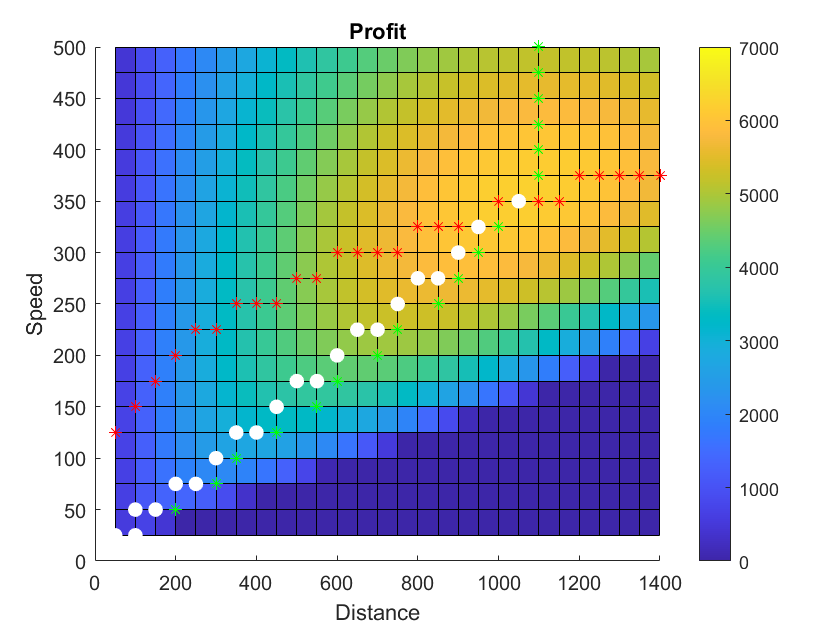

% Scale
ProfitScale=(Profit-min(min(Profit)))/(max(max(Profit))-min(min(Profit)));
PollutionScale=(Pollution-min(min(Pollution)))/(max(max(Pollution))-min(min(Pollution)));
% lambda and wighted sum
tic
WS=0;
for lambda=0:.01:1
WS=lambda*ProfitScale+(1-lambda)*(1-PollutionScale)
[ilig icol]=find(WS==max((max(WS))));
figure(1)
plot(x(icol),v(ilig),'w.','MarkerSize',25)
end

toc

Elapsed time is 0.822727 seconds.


## Test